# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

## Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

## Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir


.                       ex1_companion.mlx       gradientDescentMulti.m  warmUpExercise.m        
..                      ex1data1.txt            normalEqn.m             
computeCost.m           ex1data2.txt            plotData.m              
computeCostMulti.m      featureNormalize.m      submit.m                
ex1.mlx                 gradientDescent.m       token.mat               



## Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

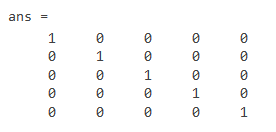

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

## 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

## 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

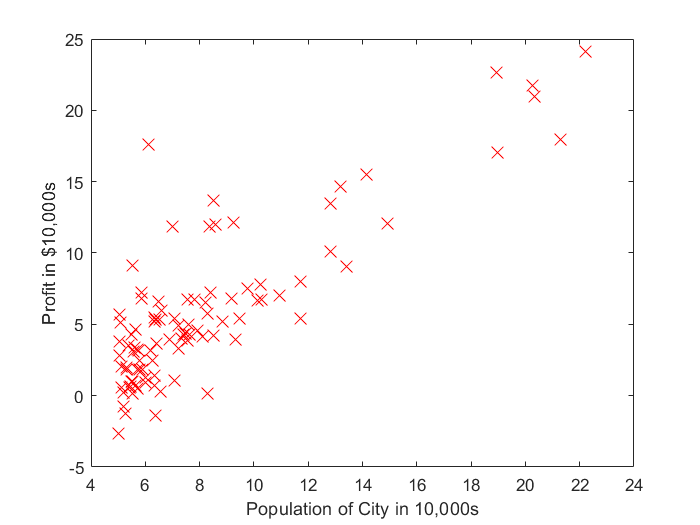

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

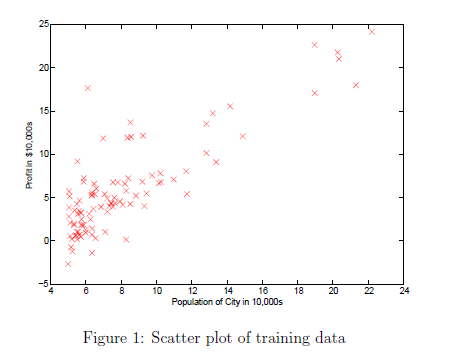

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

## 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

## 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

## 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

## 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

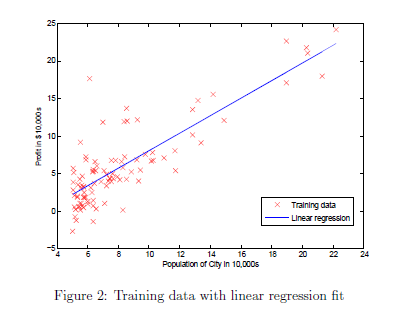    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362

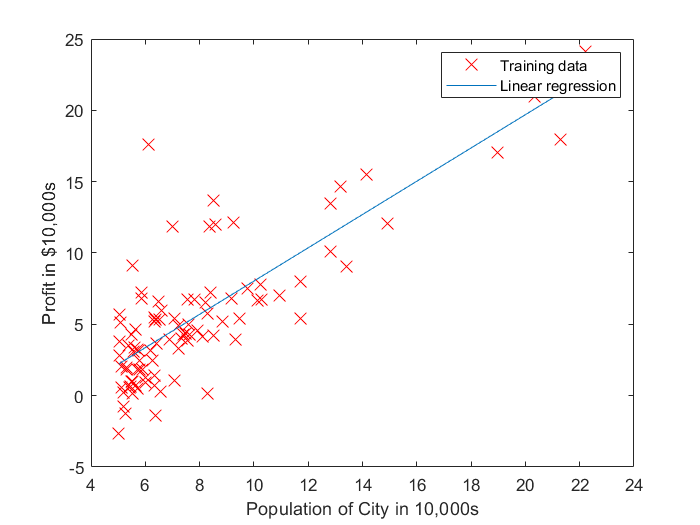


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

## 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

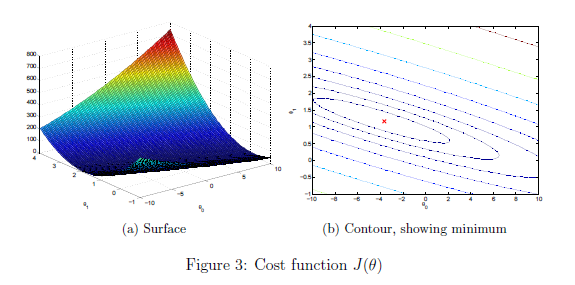

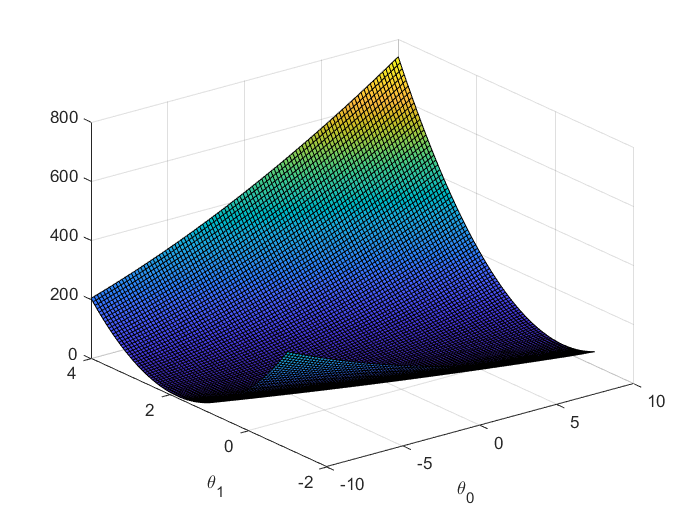

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

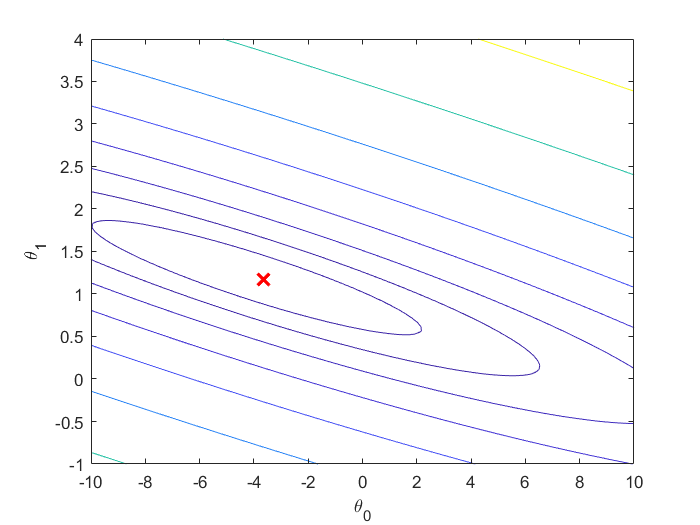


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


The remainder of this script has been set up to help you step through this exercise.

## 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

## Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

## 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

xxxx1 =      -399900
     -329900
     -369000
     -232000
     -539900
     -299900
     -314900
     -198999
     -212000
     -242500


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+06 *

   -0.3999   -0.0520    0.0894
   -0.3299    0.1663    0.0738
   -0.3690   -0.1854    0.0825
   -0.2320    0.1707    0.3568
   -0.5399   -0.6789   -0.5887
   -0.2999    0.0059   -0.3270
   -0.3149    0.1849    0.0704
   -0.1990    0.1437    0.0445
   -0.2120    0.1656    0.0474
   -0.2425    0.1546    0.0542


xxxx3 = 	1.0e+07 *

   -1.5999
   -0.4918
   -0.2544


xxxx1 = 	1.0e+05 *

   -3.6571
   -3.0234
   -3.3091
   -2.1398
   -4.8680
   -2.6016
   -2.8821
   -1.7372
   -1.8734
   -2.1634


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+06 *

   -0.3657   -0.0475    0.0818
   -0.3023    0.1524    0.0676
   -0.3309   -0.1663    0.0740
   -0.2140    0.1574    0.3291
   -0.4868   -0.6121   -0.5308
   -0.2602    0.0051   -0.2837
   -0.2882    0.1693    0.0645
   -0.1737    0.1254    0.0389
   -0.1873    0.1463    0.0419
   -0.2163    0.1379    0.0484


xxxx3 = 	1.0e+07 *

   -1.4399
   -0.4297
   -0.2025


xxxx1 = 	1.0e+05 *

   -3.3485
   -2.7728
   -2.9664
   -1.9670
   -4.3997
   -2.2501
   -2.6391
   -1.5065
   -1.6481
   -1.9250


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+06 *

   -0.3348   -0.0435    0.0749
   -0.2773    0.1398    0.0620
   -0.2966   -0.1491    0.0664
   -0.1967    0.1447    0.3025
   -0.4400   -0.5532   -0.4797
   -0.2250    0.0044   -0.2454
   -0.2639    0.1550    0.0590
   -0.1506    0.1088    0.0337
   -0.1648    0.1287    0.0369
   -0.1925    0.1227    0.0431


xxxx3 = 	1.0e+07 *

   -1.2960
   -0.3765
   -0.1592


xxxx1 = 	1.0e+05 *

   -3.0699
   -2.5450
   -2.6580
   -1.8022
   -3.9863
   -1.9390
   -2.4180
   -1.2962
   -1.4425
   -1.7079


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+06 *

   -0.3070   -0.0399    0.0687
   -0.2545    0.1283    0.0569
   -0.2658   -0.1336    0.0595
   -0.1802    0.1326    0.2771
   -0.3986   -0.5013   -0.4347
   -0.1939    0.0038   -0.2114
   -0.2418    0.1420    0.0541
   -0.1296    0.0936    0.0290
   -0.1443    0.1127    0.0323
   -0.1708    0.1089    0.0382


xxxx3 = 	1.0e+07 *

   -1.1664
   -0.3310
   -0.1229


xxxx1 = 	1.0e+05 *

   -2.8184
   -2.3382
   -2.3803
   -1.6461
   -3.6210
   -1.6637
   -2.2170
   -1.1047
   -1.2552
   -1.5105


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+06 *

   -0.2818   -0.0366    0.0630
   -0.2338    0.1179    0.0523
   -0.2380   -0.1196    0.0532
   -0.1646    0.1211    0.2531
   -0.3621   -0.4553   -0.3948
   -0.1664    0.0033   -0.1814
   -0.2217    0.1302    0.0496
   -0.1105    0.0797    0.0247
   -0.1255    0.0980    0.0281
   -0.1510    0.0963    0.0338


xxxx3 = 	1.0e+07 *

   -1.0497
   -0.2918
   -0.0928


xxxx1 = 	1.0e+05 *

   -2.5914
   -2.1506
   -2.1302
   -1.4988
   -3.2981
   -1.4201
   -2.0346
   -0.9306
   -1.0848
   -1.3311


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+06 *

   -0.2591   -0.0337    0.0580
   -0.2151    0.1084    0.0481
   -0.2130   -0.1070    0.0476
   -0.1499    0.1103    0.2305
   -0.3298   -0.4147   -0.3596
   -0.1420    0.0028   -0.1548
   -0.2035    0.1195    0.0455
   -0.0931    0.0672    0.0208
   -0.1085    0.0847    0.0243
   -0.1331    0.0849    0.0298


xxxx3 = 	1.0e+06 *

   -9.4475
   -2.5819
   -0.6770


xxxx1 = 	1.0e+05 *

   -2.3865
   -1.9805
   -1.9048
   -1.3604
   -3.0123
   -1.2044
   -1.8690
   -0.7724
   -0.9299
   -1.1684


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+06 *

   -0.2386   -0.0310    0.0534
   -0.1981    0.0999    0.0443
   -0.1905   -0.0957    0.0426
   -0.1360    0.1001    0.2092
   -0.3012   -0.3788   -0.3285
   -0.1204    0.0024   -0.1313
   -0.1869    0.1098    0.0418
   -0.0772    0.0558    0.0173
   -0.0930    0.0726    0.0208
   -0.1168    0.0745    0.0261


xxxx3 = 	1.0e+06 *

   -8.5027
   -2.2921
   -0.4692


xxxx1 = 	1.0e+05 *

   -2.2015
   -1.8264
   -1.7016
   -1.2307
   -2.7592
   -1.0136
   -1.7190
   -0.6290
   -0.7893
   -1.0208


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+05 *

   -2.2015   -0.2862    0.4924
   -1.8264    0.9209    0.4085
   -1.7016   -0.8550    0.3806
   -1.2307    0.9054    1.8925
   -2.7592   -3.4696   -3.0086
   -1.0136    0.0200   -1.1052
   -1.7190    1.0095    0.3845
   -0.6290    0.4540    0.1407
   -0.7893    0.6165    0.1765
   -1.0208    0.6508    0.2283


xxxx3 = 	1.0e+06 *

   -7.6525
   -2.0421
   -0.2977


xxxx1 = 	1.0e+05 *

   -2.0344
   -1.6869
   -1.5184
   -1.1096
   -2.5348
   -0.8447
   -1.5831
   -0.4989
   -0.6618
   -0.8871


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+05 *

   -2.0344   -0.2645    0.4551
   -1.6869    0.8505    0.3773
   -1.5184   -0.7630    0.3396
   -1.1096    0.8163    1.7063
   -2.5348   -3.1875   -2.7640
   -0.8447    0.0167   -0.9211
   -1.5831    0.9297    0.3541
   -0.4989    0.3602    0.1116
   -0.6618    0.5169    0.1480
   -0.8871    0.5656    0.1984


xxxx3 = 	1.0e+06 *

   -6.8872
   -1.8259
   -0.1566


xxxx1 = 	1.0e+05 *

   -1.8836
   -1.5607
   -1.3531
   -0.9967
   -2.3358
   -0.6953
   -1.4601
   -0.3812
   -0.5464
   -0.7661


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+05 *

   -1.8836   -0.2449    0.4213
   -1.5607    0.7869    0.3491
   -1.3531   -0.6799    0.3027
   -0.9967    0.7333    1.5328
   -2.3358   -2.9372   -2.5470
   -0.6953    0.0137   -0.7582
   -1.4601    0.8574    0.3266
   -0.3812    0.2752    0.0853
   -0.5464    0.4267    0.1222
   -0.7661    0.4884    0.1713


xxxx3 = 	1.0e+06 *

   -6.1985
   -1.6386
   -0.0412


xxxx1 = 	1.0e+05 *

   -1.7474
   -1.4466
   -1.2039
   -0.8919
   -2.1591
   -0.5632
   -1.3489
   -0.2747
   -0.4419
   -0.6566


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+05 *

   -1.7474   -0.2272    0.3908
   -1.4466    0.7294    0.3236
   -1.2039   -0.6049    0.2693
   -0.8919    0.6562    1.3715
   -2.1591   -2.7150   -2.3543
   -0.5632    0.0111   -0.6141
   -1.3489    0.7921    0.3017
   -0.2747    0.1983    0.0614
   -0.4419    0.3451    0.0988
   -0.6566    0.4186    0.1469


xxxx3 = 	1.0e+06 *

   -5.5786
   -1.4760
    0.0526


xxxx1 = 	1.0e+05 *

   -1.6243
   -1.3435
   -1.0692
   -0.7946
   -2.0021
   -0.4463
   -1.2484
   -0.1784
   -0.3475
   -0.5577


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+05 *

   -1.6243   -0.2112    0.3633
   -1.3435    0.6774    0.3005
   -1.0692   -0.5372    0.2391
   -0.7946    0.5846    1.2218
   -2.0021   -2.5176   -2.1832
   -0.4463    0.0088   -0.4867
   -1.2484    0.7331    0.2792
   -0.1784    0.1288    0.0399
   -0.3475    0.2714    0.0777
   -0.5577    0.3556    0.1247


xxxx3 = 	1.0e+06 *

   -5.0208
   -1.3344
    0.1283


xxxx1 = 	1.0e+05 *

   -1.5132
   -1.2504
   -0.9475
   -0.7044
   -1.8626
   -0.3430
   -1.1576
   -0.0915
   -0.2622
   -0.4683


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 = 	1.0e+05 *

   -1.5132   -0.1967    0.3385
   -1.2504    0.6304    0.2797
   -0.9475   -0.4761    0.2119
   -0.7044    0.5183    1.0832
   -1.8626   -2.3422   -2.0310
   -0.3430    0.0068   -0.3740
   -1.1576    0.6798    0.2589
   -0.0915    0.0660    0.0205
   -0.2622    0.2048    0.0587
   -0.4683    0.2986    0.1048


xxxx3 =    -4.5187
   -1.2108
    0.1889


xxxx1 =    -1.4128
   -1.1663
   -0.8375
   -0.6210
   -1.7384
   -0.2518
   -1.0757
   -0.0130
   -0.1853
   -0.3877


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -1.4128   -0.1837    0.3160
   -1.1663    0.5881    0.2609
   -0.8375   -0.4208    0.1873
   -0.6210    0.4569    0.9550
   -1.7384   -2.1860   -1.8956
   -0.2518    0.0050   -0.2745
   -1.0757    0.6317    0.2406
   -0.0130    0.0094    0.0029
   -0.1853    0.1447    0.0414
   -0.3877    0.2472    0.0867


xxxx3 =    -4.0668
   -1.1027
    0.2368


xxxx1 =    -1.3221
   -1.0905
   -0.7380
   -0.5440
   -1.6279
   -0.1712
   -1.0019
    0.0577
   -0.1160
   -0.3150


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -1.3221   -0.1719    0.2957
   -1.0905    0.5498    0.2439
   -0.7380   -0.3708    0.1651
   -0.5440    0.4003    0.8366
   -1.6279   -2.0470   -1.7751
   -0.1712    0.0034   -0.1867
   -1.0019    0.5883    0.2241
    0.0577   -0.0417   -0.0129
   -0.1160    0.0906    0.0259
   -0.3150    0.2009    0.0705


xxxx3 =    -3.6601
   -1.0077
    0.2740


xxxx1 =    -1.2402
   -1.0222
   -0.6481
   -0.4730
   -1.5294
   -0.1001
   -0.9353
    0.1214
   -0.0535
   -0.2495


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -1.2402   -0.1612    0.2774
   -1.0222    0.5154    0.2286
   -0.6481   -0.3256    0.1450
   -0.4730    0.3480    0.7273
   -1.5294   -1.9232   -1.6677
   -0.1001    0.0020   -0.1092
   -0.9353    0.5492    0.2092
    0.1214   -0.0876   -0.0272
   -0.0535    0.0418    0.0120
   -0.2495    0.1591    0.0558


xxxx3 =    -3.2941
   -0.9241
    0.3024


xxxx1 =    -1.1661
   -0.9605
   -0.5667
   -0.4074
   -1.4416
   -0.0374
   -0.8753
    0.1787
    0.0026
   -0.1905


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -1.1661   -0.1516    0.2608
   -0.9605    0.4843    0.2148
   -0.5667   -0.2847    0.1267
   -0.4074    0.2998    0.6266
   -1.4416   -1.8128   -1.5720
   -0.0374    0.0007   -0.0408
   -0.8753    0.5140    0.1958
    0.1787   -0.1290   -0.0400
    0.0026   -0.0020   -0.0006
   -0.1905    0.1215    0.0426


xxxx3 =    -2.9647
   -0.8502
    0.3235


xxxx1 =    -1.0991
   -0.9050
   -0.4930
   -0.3471
   -1.3633
    0.0178
   -0.8213
    0.2303
    0.0531
   -0.1374


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -1.0991   -0.1429    0.2458
   -0.9050    0.4563    0.2024
   -0.4930   -0.2477    0.1103
   -0.3471    0.2554    0.5337
   -1.3633   -1.7143   -1.4866
    0.0178   -0.0004    0.0194
   -0.8213    0.4823    0.1837
    0.2303   -0.1663   -0.0515
    0.0531   -0.0415   -0.0119
   -0.1374    0.0876    0.0307


xxxx3 =    -2.6682
   -0.7848
    0.3384


xxxx1 =    -1.0385
   -0.8551
   -0.4262
   -0.2915
   -1.2934
    0.0664
   -0.7727
    0.2766
    0.0985
   -0.0897


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -1.0385   -0.1350    0.2323
   -0.8551    0.4311    0.1913
   -0.4262   -0.2141    0.0953
   -0.2915    0.2145    0.4483
   -1.2934   -1.6264   -1.4103
    0.0664   -0.0013    0.0724
   -0.7727    0.4538    0.1728
    0.2766   -0.1997   -0.0619
    0.0985   -0.0769   -0.0220
   -0.0897    0.0572    0.0201


xxxx3 =    -2.4014
   -0.7265
    0.3483


xxxx1 =    -0.9838
   -0.8101
   -0.3657
   -0.2404
   -1.2309
    0.1091
   -0.7290
    0.3182
    0.1391
   -0.0468


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.9838   -0.1279    0.2200
   -0.8101    0.4085    0.1812
   -0.3657   -0.1837    0.0818
   -0.2404    0.1769    0.3697
   -1.2309   -1.5479   -1.3422
    0.1091   -0.0022    0.1189
   -0.7290    0.4281    0.1631
    0.3182   -0.2297   -0.0712
    0.1391   -0.1087   -0.0311
   -0.0468    0.0298    0.0105


xxxx3 =    -2.1613
   -0.6745
    0.3540


xxxx1 =    -0.9342
   -0.7697
   -0.3108
   -0.1934
   -1.1751
    0.1466
   -0.6898
    0.3555
    0.1756
   -0.0083


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.9342   -0.1215    0.2090
   -0.7697    0.3881    0.1722
   -0.3108   -0.1562    0.0695
   -0.1934    0.1423    0.2974
   -1.1751   -1.4777   -1.2814
    0.1466   -0.0029    0.1598
   -0.6898    0.4051    0.1543
    0.3555   -0.2567   -0.0795
    0.1756   -0.1371   -0.0393
   -0.0083    0.0053    0.0019


xxxx3 =    -1.9452
   -0.6279
    0.3564


xxxx1 =    -0.8894
   -0.7333
   -0.2610
   -0.1502
   -1.1252
    0.1794
   -0.6546
    0.3890
    0.2082
    0.0263


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.8894   -0.1156    0.1989
   -0.7333    0.3697    0.1640
   -0.2610   -0.1311    0.0584
   -0.1502    0.1105    0.2310
   -1.1252   -1.4149   -1.2269
    0.1794   -0.0035    0.1957
   -0.6546    0.3844    0.1464
    0.3890   -0.2808   -0.0870
    0.2082   -0.1626   -0.0466
    0.0263   -0.0167   -0.0059


xxxx3 =    -1.7506
   -0.5860
    0.3559


xxxx1 =    -0.8489
   -0.7007
   -0.2158
   -0.1105
   -1.0805
    0.2082
   -0.6229
    0.4189
    0.2374
    0.0573


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.8489   -0.1104    0.1899
   -0.7007    0.3533    0.1567
   -0.2158   -0.1084    0.0483
   -0.1105    0.0813    0.1699
   -1.0805   -1.3587   -1.1782
    0.2082   -0.0041    0.2270
   -0.6229    0.3658    0.1393
    0.4189   -0.3024   -0.0937
    0.2374   -0.1855   -0.0531
    0.0573   -0.0365   -0.0128


xxxx3 =    -1.5756
   -0.5481
    0.3532


xxxx1 =    -0.8121
   -0.6714
   -0.1747
   -0.0740
   -1.0405
    0.2333
   -0.5946
    0.4457
    0.2635
    0.0850


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.8121   -0.1056    0.1817
   -0.6714    0.3385    0.1502
   -0.1747   -0.0878    0.0391
   -0.0740    0.0544    0.1137
   -1.0405   -1.3085   -1.1346
    0.2333   -0.0046    0.2544
   -0.5946    0.3492    0.1330
    0.4457   -0.3217   -0.0997
    0.2635   -0.2058   -0.0589
    0.0850   -0.0542   -0.0190


xxxx3 =    -1.4180
   -0.5138
    0.3486


xxxx1 =    -0.7789
   -0.6450
   -0.1374
   -0.0404
   -1.0047
    0.2551
   -0.5692
    0.4696
    0.2868
    0.1099


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.7789   -0.1013    0.1742
   -0.6450    0.3252    0.1443
   -0.1374   -0.0690    0.0307
   -0.0404    0.0297    0.0622
   -1.0047   -1.2634   -1.0956
    0.2551   -0.0050    0.2782
   -0.5692    0.3342    0.1273
    0.4696   -0.3390   -0.1050
    0.2868   -0.2240   -0.0642
    0.1099   -0.0701   -0.0246


xxxx3 =    -1.2762
   -0.4826
    0.3427


xxxx1 =    -7.4878
   -6.2143
   -1.0346
   -0.0962
   -9.7260
    2.7414
   -5.4642
    4.9101
    3.0760
    1.3213


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.7488   -0.0973    0.1675
   -0.6214    0.3133    0.1390
   -0.1035   -0.0520    0.0231
   -0.0096    0.0071    0.0148
   -0.9726   -1.2230   -1.0605
    0.2741   -0.0054    0.2989
   -0.5464    0.3209    0.1222
    0.4910   -0.3545   -0.1098
    0.3076   -0.2402   -0.0688
    0.1321   -0.0842   -0.0296


xxxx3 =    -1.1486
   -0.4542
    0.3356


xxxx1 =    -7.2149
   -6.0027
   -0.7256
    0.1868
   -9.4379
    2.9060
   -5.2606
    5.1007
    3.2609
    1.5200


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.7215   -0.0938    0.1614
   -0.6003    0.3026    0.1343
   -0.0726   -0.0365    0.0162
    0.0187   -0.0137   -0.0287
   -0.9438   -1.1868   -1.0291
    0.2906   -0.0057    0.3169
   -0.5261    0.3089    0.1177
    0.5101   -0.3682   -0.1141
    0.3261   -0.2547   -0.0729
    0.1520   -0.0969   -0.0340


xxxx3 =    -1.0337
   -0.4281
    0.3276


xxxx1 =    -6.9675
   -5.8131
   -0.4443
    0.4470
   -9.1794
    3.0481
   -5.0786
    5.2705
    3.4253
    1.6975


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.6967   -0.0906    0.1558
   -0.5813    0.2931    0.1300
   -0.0444   -0.0223    0.0099
    0.0447   -0.0329   -0.0687
   -0.9179   -1.1543   -1.0009
    0.3048   -0.0060    0.3324
   -0.5079    0.2982    0.1136
    0.5270   -0.3805   -0.1179
    0.3425   -0.2675   -0.0766
    0.1697   -0.1082   -0.0380


xxxx3 =    -9.3036
   -4.0418
    3.1904


xxxx1 =    -6.7432
   -5.6433
   -0.1880
    0.6860
   -8.9474
    3.1704
   -4.9159
    5.4215
    3.5712
    1.8558


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.6743   -0.0877    0.1508
   -0.5643    0.2845    0.1262
   -0.0188   -0.0094    0.0042
    0.0686   -0.0505   -0.1055
   -0.8947   -1.1251   -0.9756
    0.3170   -0.0063    0.3457
   -0.4916    0.2887    0.1100
    0.5422   -0.3914   -0.1213
    0.3571   -0.2789   -0.0799
    0.1856   -0.1183   -0.0415


xxxx3 =    -8.3732
   -3.8211
    3.0996


xxxx1 =    -6.5397
   -5.4914
    0.0458
    0.9058
   -8.7389
    3.2750
   -4.7708
    5.5558
    3.7006
    1.9969


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.6540   -0.0850    0.1463
   -0.5491    0.2769    0.1228
    0.0046    0.0023   -0.0010
    0.0906   -0.0666   -0.1393
   -0.8739   -1.0989   -0.9529
    0.3275   -0.0065    0.3571
   -0.4771    0.2802    0.1067
    0.5556   -0.4011   -0.1243
    0.3701   -0.2890   -0.0828
    0.1997   -0.1273   -0.0447


xxxx3 =    -7.5359
   -3.6170
    3.0057


xxxx1 =    -6.3550
   -5.3556
    0.2591
    1.1079
   -8.5515
    3.3641
   -4.6413
    5.6748
    3.8152
    2.1224


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.6355   -0.0826    0.1421
   -0.5356    0.2700    0.1198
    0.0259    0.0130   -0.0058
    0.1108   -0.0815   -0.1704
   -0.8552   -1.0753   -0.9325
    0.3364   -0.0066    0.3668
   -0.4641    0.2726    0.1038
    0.5675   -0.4097   -0.1269
    0.3815   -0.2980   -0.0853
    0.2122   -0.1353   -0.0475


xxxx3 =    -6.7823
   -3.4277
    2.9097


xxxx1 =    -6.1874
   -5.2342
    0.4539
    1.2937
   -8.3830
    3.4395
   -4.5260
    5.7804
    3.9164
    2.2341


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.6187   -0.0804    0.1384
   -0.5234    0.2639    0.1171
    0.0454    0.0228   -0.0102
    0.1294   -0.0952   -0.1989
   -0.8383   -1.0541   -0.9141
    0.3439   -0.0068    0.3750
   -0.4526    0.2658    0.1012
    0.5780   -0.4173   -0.1293
    0.3916   -0.3059   -0.0876
    0.2234   -0.1424   -0.0500


xxxx3 =    -6.1041
   -3.2517
    2.8128


xxxx1 =    -6.0351
   -5.1258
    0.6319
    1.4647
   -8.2314
    3.5027
   -4.4234
    5.8737
    4.0056
    2.3332


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.6035   -0.0785    0.1350
   -0.5126    0.2584    0.1147
    0.0632    0.0318   -0.0141
    0.1465   -0.1078   -0.2252
   -0.8231   -1.0351   -0.8976
    0.3503   -0.0069    0.3819
   -0.4423    0.2598    0.0989
    0.5874   -0.4240   -0.1314
    0.4006   -0.3128   -0.0896
    0.2333   -0.1488   -0.0522


xxxx3 =    -5.4937
   -3.0876
    2.7157


xxxx1 =    -5.8968
   -5.0291
    0.7947
    1.6221
   -8.0949
    3.5553
   -4.3321
    5.9561
    4.0841
    2.4212


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.5897   -0.0767    0.1319
   -0.5029    0.2536    0.1125
    0.0795    0.0399   -0.0178
    0.1622   -0.1193   -0.2494
   -0.8095   -1.0179   -0.8827
    0.3555   -0.0070    0.3877
   -0.4332    0.2544    0.0969
    0.5956   -0.4300   -0.1332
    0.4084   -0.3190   -0.0914
    0.2421   -0.1544   -0.0542


xxxx3 =    -4.9443
   -2.9342
    2.6192


xxxx1 =    -5.7710
   -4.9429
    0.9438
    1.7671
   -7.9720
    3.5985
   -4.2511
    6.0287
    4.1530
    2.4990


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -0.5771   -0.0750    0.1291
   -0.4943    0.2492    0.1106
    0.0944    0.0474   -0.0211
    0.1767   -0.1300   -0.2717
   -0.7972   -1.0025   -0.8693
    0.3598   -0.0071    0.3924
   -0.4251    0.2496    0.0951
    0.6029   -0.4352   -0.1348
    0.4153   -0.3244   -0.0929
    0.2499   -0.1593   -0.0559


xxxx3 =    -4.4499
   -2.7906
    2.5236


xxxx1 =    -5.6566
   -4.8662
    1.0803
    1.9006
   -7.8612
    3.6335
   -4.1793
    6.0925
    4.2133
    2.5679


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -5.6566   -0.7354    1.2652
   -4.8662    2.4535    1.0884
    1.0803    0.5428   -0.2416
    1.9006   -1.3983   -2.9227
   -7.8612   -9.8853   -8.5720
    3.6335   -0.0717    3.9620
   -4.1793    2.4543    0.9348
    6.0925   -4.3980   -1.3627
    4.2133   -3.2907   -0.9424
    2.5679   -1.6372   -0.5744


xxxx3 =    -4.0049
   -2.6558
    2.4296


xxxx1 =    -5.5525
   -4.7979
    1.2054
    2.0238
   -7.7613
    3.6612
   -4.1157
    6.1485
    4.2660
    2.6286


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -5.5525   -0.7219    1.2420
   -4.7979    2.4190    1.0732
    1.2054    0.6057   -0.2696
    2.0238   -1.4889   -3.1121
   -7.7613   -9.7596   -8.4630
    3.6612   -0.0722    3.9922
   -4.1157    2.4169    0.9206
    6.1485   -4.4385   -1.3753
    4.2660   -3.3318   -0.9542
    2.6286   -1.6759   -0.5880


xxxx3 =    -3.6044
   -2.5290
    2.3373


xxxx1 =    -5.4577
   -4.7372
    1.3203
    2.1373
   -7.6712
    3.6826
   -4.0595
    6.1974
    4.3117
    2.6821


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -5.4577   -0.7096    1.2207
   -4.7372    2.3884    1.0596
    1.3203    0.6634   -0.2953
    2.1373   -1.5725   -3.2867
   -7.6712   -9.6463   -8.3648
    3.6826   -0.0727    4.0156
   -4.0595    2.3839    0.9080
    6.1974   -4.4738   -1.3862
    4.3117   -3.3676   -0.9644
    2.6821   -1.7100   -0.5999


xxxx3 =    -3.2440
   -2.4096
    2.2472


xxxx1 =    -5.3713
   -4.6833
    1.4258
    2.2422
   -7.5898
    3.6985
   -4.0099
    6.2401
    4.3514
    2.7291


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -5.3713   -0.6983    1.2014
   -4.6833    2.3613    1.0475
    1.4258    0.7164   -0.3189
    2.2422   -1.6496   -3.4479
   -7.5898   -9.5440   -8.2761
    3.6985   -0.0730    4.0329
   -4.0099    2.3548    0.8969
    6.2401   -4.5046   -1.3958
    4.3514   -3.3986   -0.9733
    2.7291   -1.7400   -0.6104


xxxx3 =    -2.9196
   -2.2969
    2.1593


xxxx1 =    -5.2926
   -4.6356
    1.5227
    2.3390
   -7.5163
    3.7095
   -3.9662
    6.2773
    4.3856
    2.7704


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -5.2926   -0.6881    1.1838
   -4.6356    2.3372    1.0369
    1.5227    0.7651   -0.3406
    2.3390   -1.7208   -3.5968
   -7.5163   -9.4516   -8.1959
    3.7095   -0.0732    4.0449
   -3.9662    2.3291    0.8871
    6.2773   -4.5314   -1.4041
    4.3856   -3.4253   -0.9810
    2.7704   -1.7663   -0.6197


xxxx3 =    -2.6276
   -2.1905
    2.0738


xxxx1 =    -5.2207
   -4.5933
    1.6119
    2.4285
   -7.4499
    3.7164
   -3.9278
    6.3094
    4.4150
    2.8064


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -5.2207   -0.6787    1.1677
   -4.5933    2.3159    1.0274
    1.6119    0.8099   -0.3605
    2.4285   -1.7867   -3.7344
   -7.4499   -9.3681   -8.1235
    3.7164   -0.0733    4.0524
   -3.9278    2.3066    0.8786
    6.3094   -4.5546   -1.4113
    4.4150   -3.4482   -0.9875
    2.8064   -1.7893   -0.6277


xxxx3 =    -2.3649
   -2.0897
    1.9909


xxxx1 =    -5.1551
   -4.5559
    1.6940
    2.5112
   -7.3899
    3.7196
   -3.8941
    6.3371
    4.4401
    2.8379


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -5.1551   -0.6702    1.1531
   -4.5559    2.2971    1.0190
    1.6940    0.8512   -0.3789
    2.5112   -1.8475   -3.8616
   -7.3899   -9.2926   -8.0581
    3.7196   -0.0734    4.0560
   -3.8941    2.2868    0.8710
    6.3371   -4.5746   -1.4174
    4.4401   -3.4678   -0.9931
    2.8379   -1.8094   -0.6348


xxxx3 =    -2.1284
   -1.9943
    1.9106


xxxx1 =    -5.0953
   -4.5229
    1.7697
    2.5878
   -7.3356
    3.7198
   -3.8647
    6.3608
    4.4613
    2.8652


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -5.0953   -0.6624    1.1397
   -4.5229    2.2804    1.0117
    1.7697    0.8893   -0.3958
    2.5878   -1.9039   -3.9794
   -7.3356   -9.2243   -7.9988
    3.7198   -0.0734    4.0561
   -3.8647    2.2695    0.8644
    6.3608   -4.5918   -1.4228
    4.4613   -3.4844   -0.9979
    2.8652   -1.8268   -0.6409


xxxx3 =    -1.9155
   -1.9038
    1.8329


xxxx1 =    -5.0405
   -4.4939
    1.8396
    2.6587
   -7.2864
    3.7172
   -3.8390
    6.3811
    4.4792
    2.8889


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -5.0405   -0.6553    1.1274
   -4.4939    2.2658    1.0052
    1.8396    0.9243   -0.4115
    2.6587   -1.9561   -4.0885
   -7.2864   -9.1625   -7.9452
    3.7172   -0.0733    4.0533
   -3.8390    2.2544    0.8587
    6.3811   -4.6064   -1.4273
    4.4792   -3.4983   -1.0019
    2.8889   -1.8419   -0.6462


xxxx3 =    -1.7240
   -1.8180
    1.7578


xxxx1 =    -4.9904
   -4.4683
    1.9041
    2.7244
   -7.2419
    3.7123
   -3.8166
    6.3982
    4.4940
    2.9092


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.9904   -0.6488    1.1162
   -4.4683    2.2529    0.9995
    1.9041    0.9567   -0.4259
    2.7244   -2.0044   -4.1896
   -7.2419   -9.1065   -7.8967
    3.7123   -0.0733    4.0480
   -3.8166    2.2413    0.8537
    6.3982   -4.6187   -1.4311
    4.4940   -3.5099   -1.0052
    2.9092   -1.8549   -0.6507


xxxx3 =    -1.5516
   -1.7364
    1.6854


xxxx1 =    -4.9446
   -4.4459
    1.9637
    2.7854
   -7.2015
    3.7055
   -3.7973
    6.4126
    4.5062
    2.9267


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.9446   -0.6428    1.1060
   -4.4459    2.2416    0.9944
    1.9637    0.9867   -0.4392
    2.7854   -2.0493   -4.2833
   -7.2015   -9.0557   -7.8526
    3.7055   -0.0731    4.0405
   -3.7973    2.2299    0.8494
    6.4126   -4.6291   -1.4343
    4.5062   -3.5194   -1.0079
    2.9267   -1.8660   -0.6546


xxxx3 =    -1.3964
   -1.6588
    1.6156


xxxx1 =    -4.9026
   -4.4263
    2.0188
    2.8420
   -7.1649
    3.6970
   -3.7806
    6.4245
    4.5160
    2.9416


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.9026   -0.6374    1.0966
   -4.4263    2.2317    0.9901
    2.0188    1.0144   -0.4516
    2.8420   -2.0909   -4.3704
   -7.1649   -9.0097   -7.8127
    3.6970   -0.0729    4.0313
   -3.7806    2.2201    0.8456
    6.4245   -4.6377   -1.4370
    4.5160   -3.5271   -1.0101
    2.9416   -1.8755   -0.6580


xxxx3 =    -1.2568
   -1.5850
    1.5484


xxxx1 =    -4.8641
   -4.4092
    2.0698
    2.8946
   -7.1317
    3.6872
   -3.7663
    6.4342
    4.5238
    2.9542


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.8641   -0.6324    1.0880
   -4.4092    2.2231    0.9862
    2.0698    1.0400   -0.4630
    2.8946   -2.1296   -4.4512
   -7.1317   -8.9679   -7.7765
    3.6872   -0.0728    4.0206
   -3.7663    2.2117    0.8424
    6.4342   -4.6448   -1.4392
    4.5238   -3.5332   -1.0119
    2.9542   -1.8835   -0.6608


xxxx3 =    -1.1311
   -1.5147
    1.4837


xxxx1 =    -4.8288
   -4.3943
    2.1172
    2.9435
   -7.1015
    3.6762
   -3.7541
    6.4421
    4.5297
    2.9648


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.8288   -0.6278    1.0801
   -4.3943    2.2156    0.9829
    2.1172    1.0638   -0.4736
    2.9435   -2.1656   -4.5264
   -7.1015   -8.9300   -7.7436
    3.6762   -0.0725    4.0086
   -3.7541    2.2046    0.8397
    6.4421   -4.6504   -1.4409
    4.5297   -3.5378   -1.0132
    2.9648   -1.8903   -0.6632


xxxx3 =    -1.0180
   -1.4478
    1.4215


xxxx1 =    -4.7964
   -4.3815
    2.1611
    2.9890
   -7.0741
    3.6643
   -3.7438
    6.4483
    4.5341
    2.9736


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.7964   -0.6236    1.0728
   -4.3815    2.2091    0.9800
    2.1611    1.0859   -0.4834
    2.9890   -2.1991   -4.5964
   -7.0741   -8.8955   -7.7137
    3.6643   -0.0723    3.9956
   -3.7438    2.1985    0.8374
    6.4483   -4.6549   -1.4423
    4.5341   -3.5412   -1.0142
    2.9736   -1.8959   -0.6651


xxxx3 =    -0.9162
   -1.3840
    1.3618


xxxx1 =    -4.7666
   -4.3703
    2.2018
    3.0314
   -7.0492
    3.6516
   -3.7351
    6.4530
    4.5371
    2.9808


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.7666   -0.6197    1.0662
   -4.3703    2.2035    0.9775
    2.2018    1.1064   -0.4925
    3.0314   -2.2303   -4.6616
   -7.0492   -8.8642   -7.6865
    3.6516   -0.0721    3.9817
   -3.7351    2.1934    0.8355
    6.4530   -4.6583   -1.4434
    4.5371   -3.5436   -1.0148
    2.9808   -1.9005   -0.6667


xxxx3 =    -0.8246
   -1.3232
    1.3043


xxxx1 =    -4.7392
   -4.3608
    2.2397
    3.0709
   -7.0265
    3.6383
   -3.7279
    6.4564
    4.5388
    2.9866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.7392   -0.6161    1.0600
   -4.3608    2.1987    0.9754
    2.2397    1.1254   -0.5010
    3.0709   -2.2593   -4.7223
   -7.0265   -8.8356   -7.6618
    3.6383   -0.0718    3.9673
   -3.7279    2.1892    0.8338
    6.4564   -4.6608   -1.4441
    4.5388   -3.5449   -1.0152
    2.9866   -1.9042   -0.6680


xxxx3 =    -0.7421
   -1.2652
    1.2492


xxxx1 =    -4.7139
   -4.3526
    2.2750
    3.1078
   -7.0058
    3.6246
   -3.7220
    6.4587
    4.5396
    2.9912


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.7139   -0.6129    1.0544
   -4.3526    2.1945    0.9736
    2.2750    1.1431   -0.5089
    3.1078   -2.2865   -4.7790
   -7.0058   -8.8097   -7.6393
    3.6246   -0.0715    3.9523
   -3.7220    2.1857    0.8325
    6.4587   -4.6624   -1.4447
    4.5396   -3.5455   -1.0154
    2.9912   -1.9071   -0.6690


xxxx3 =    -0.6679
   -1.2098
    1.1963


xxxx1 =    -4.6907
   -4.3457
    2.3078
    3.1422
   -6.9870
    3.6105
   -3.7172
    6.4601
    4.5394
    2.9947


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.6907   -0.6098    1.0492
   -4.3457    2.1910    0.9720
    2.3078    1.1596   -0.5162
    3.1422   -2.3118   -4.8319
   -6.9870   -8.7860   -7.6187
    3.6105   -0.0712    3.9370
   -3.7172    2.1829    0.8314
    6.4601   -4.6634   -1.4450
    4.5394   -3.5453   -1.0153
    2.9947   -1.9093   -0.6698


xxxx3 =    -0.6011
   -1.1570
    1.1455


xxxx1 =    -4.6692
   -4.3399
    2.3384
    3.1743
   -6.9698
    3.5963
   -3.7134
    6.4605
    4.5384
    2.9972


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.6692   -0.6070    1.0444
   -4.3399    2.1881    0.9707
    2.3384    1.1750   -0.5231
    3.1743   -2.3354   -4.8814
   -6.9698   -8.7644   -7.6000
    3.5963   -0.0710    3.9214
   -3.7134    2.1806    0.8306
    6.4605   -4.6637   -1.4451
    4.5384   -3.5446   -1.0151
    2.9972   -1.9109   -0.6704


xxxx3 =    -0.5410
   -1.1065
    1.0968


xxxx1 =    -4.6494
   -4.3350
    2.3670
    3.2044
   -6.9542
    3.5819
   -3.7105
    6.4603
    4.5367
    2.9989


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.6494   -0.6045    1.0400
   -4.3350    2.1857    0.9696
    2.3670    1.1894   -0.5294
    3.2044   -2.3576   -4.9276
   -6.9542   -8.7447   -7.5829
    3.5819   -0.0707    3.9057
   -3.7105    2.1789    0.8299
    6.4603   -4.6635   -1.4450
    4.5367   -3.5433   -1.0147
    2.9989   -1.9120   -0.6708


xxxx3 =    -0.4869
   -1.0583
    1.0501


xxxx1 =    -4.6311
   -4.3310
    2.3937
    3.2326
   -6.9399
    3.5674
   -3.7083
    6.4594
    4.5345
    2.9999


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.6311   -0.6021    1.0359
   -4.3310    2.1836    0.9687
    2.3937    1.2028   -0.5354
    3.2326   -2.3783   -4.9709
   -6.9399   -8.7267   -7.5673
    3.5674   -0.0704    3.8900
   -3.7083    2.1777    0.8295
    6.4594   -4.6629   -1.4448
    4.5345   -3.5415   -1.0143
    2.9999   -1.9127   -0.6710


xxxx3 =    -0.4382
   -1.0123
    1.0053


xxxx1 =    -4.6142
   -4.3277
    2.4186
    3.2589
   -6.9268
    3.5530
   -3.7069
    6.4579
    4.5318
    3.0003


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.6142   -0.5999    1.0321
   -4.3277    2.1820    0.9680
    2.4186    1.2153   -0.5410
    3.2589   -2.3977   -5.0115
   -6.9268   -8.7102   -7.5531
    3.5530   -0.0701    3.8742
   -3.7069    2.1768    0.8291
    6.4579   -4.6619   -1.4445
    4.5318   -3.5394   -1.0136
    3.0003   -1.9129   -0.6711


xxxx3 =    -3.9439
   -9.6831
    9.6240


xxxx1 =    -4.5986
   -4.3252
    2.4419
    3.2837
   -6.9148
    3.5387
   -3.7060
    6.4560
    4.5286
    3.0001


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.5986   -0.5979    1.0286
   -4.3252    2.1807    0.9674
    2.4419    1.2270   -0.5462
    3.2837   -2.4159   -5.0495
   -6.9148   -8.6952   -7.5400
    3.5387   -0.0698    3.8586
   -3.7060    2.1763    0.8289
    6.4560   -4.6605   -1.4441
    4.5286   -3.5370   -1.0129
    3.0001   -1.9128   -0.6711


xxxx3 =    -3.5495
   -9.2628
    9.2127


xxxx1 =    -4.5841
   -4.3232
    2.4638
    3.3069
   -6.9038
    3.5244
   -3.7057
    6.4537
    4.5252
    2.9995


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.5841   -0.5960    1.0253
   -4.3232    2.1797    0.9670
    2.4638    1.2380   -0.5511
    3.3069   -2.4329   -5.0852
   -6.9038   -8.6814   -7.5281
    3.5244   -0.0695    3.8431
   -3.7057    2.1761    0.8289
    6.4537   -4.6588   -1.4435
    4.5252   -3.5343   -1.0122
    2.9995   -1.9124   -0.6709


xxxx3 =    -3.1946
   -8.8611
    8.8187


xxxx1 =    -4.5706
   -4.3217
    2.4842
    3.3286
   -6.8938
    3.5104
   -3.7057
    6.4511
    4.5215
    2.9985


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.5706   -0.5942    1.0223
   -4.3217    2.1789    0.9666
    2.4842    1.2483   -0.5557
    3.3286   -2.4490   -5.1187
   -6.8938   -8.6688   -7.5171
    3.5104   -0.0693    3.8278
   -3.7057    2.1762    0.8289
    6.4511   -4.6569   -1.4430
    4.5215   -3.5314   -1.0113
    2.9985   -1.9117   -0.6707


xxxx3 =    -2.8751
   -8.4772
    8.4412


xxxx1 =    -4.5582
   -4.3206
    2.5034
    3.3491
   -6.8846
    3.4966
   -3.7062
    6.4482
    4.5175
    2.9971


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.5582   -0.5926    1.0195
   -4.3206    2.1784    0.9664
    2.5034    1.2579   -0.5600
    3.3491   -2.4640   -5.1501
   -6.8846   -8.6572   -7.5071
    3.4966   -0.0690    3.8127
   -3.7062    2.1764    0.8290
    6.4482   -4.6549   -1.4423
    4.5175   -3.5283   -1.0105
    2.9971   -1.9109   -0.6704


xxxx3 =    -2.5876
   -8.1101
    8.0797


xxxx1 =    -4.5466
   -4.3200
    2.5215
    3.3683
   -6.8761
    3.4830
   -3.7070
    6.4451
    4.5134
    2.9955


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.5466   -0.5911    1.0170
   -4.3200    2.1781    0.9663
    2.5215    1.2670   -0.5640
    3.3683   -2.4782   -5.1797
   -6.8761   -8.6466   -7.4978
    3.4830   -0.0687    3.7979
   -3.7070    2.1769    0.8292
    6.4451   -4.6526   -1.4416
    4.5134   -3.5251   -1.0095
    2.9955   -1.9098   -0.6700


xxxx3 =    -2.3288
   -7.7592
    7.7334


xxxx1 =    -4.5358
   -4.3197
    2.5384
    3.3865
   -6.8683
    3.4697
   -3.7080
    6.4418
    4.5091
    2.9936


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.5358   -0.5897    1.0145
   -4.3197    2.1779    0.9662
    2.5384    1.2755   -0.5678
    3.3865   -2.4915   -5.2076
   -6.8683   -8.6368   -7.4894
    3.4697   -0.0685    3.7834
   -3.7080    2.1775    0.8294
    6.4418   -4.6502   -1.4409
    4.5091   -3.5217   -1.0086
    2.9936   -1.9086   -0.6696


xxxx3 =    -2.0960
   -7.4236
    7.4017


xxxx1 =    -4.5258
   -4.3196
    2.5543
    3.4035
   -6.8612
    3.4567
   -3.7093
    6.4384
    4.5048
    2.9915


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.5258   -0.5884    1.0123
   -4.3196    2.1779    0.9662
    2.5543    1.2835   -0.5713
    3.4035   -2.5040   -5.2338
   -6.8612   -8.6278   -7.4816
    3.4567   -0.0682    3.7692
   -3.7093    2.1783    0.8297
    6.4384   -4.6478   -1.4401
    4.5048   -3.5183   -1.0076
    2.9915   -1.9073   -0.6691


xxxx3 =    -1.8864
   -7.1027
    7.0842


xxxx1 =    -4.5164
   -4.3199
    2.5693
    3.4196
   -6.8546
    3.4439
   -3.7108
    6.4349
    4.5004
    2.9892


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.5164   -0.5872    1.0102
   -4.3199    2.1780    0.9662
    2.5693    1.2910   -0.5747
    3.4196   -2.5159   -5.2585
   -6.8546   -8.6195   -7.4744
    3.4439   -0.0680    3.7553
   -3.7108    2.1791    0.8300
    6.4349   -4.6452   -1.4393
    4.5004   -3.5149   -1.0066
    2.9892   -1.9059   -0.6686


xxxx3 =    -1.6977
   -6.7958
    6.7801


xxxx1 =    -4.5077
   -4.3203
    2.5834
    3.4347
   -6.8486
    3.4315
   -3.7125
    6.4313
    4.4959
    2.9869


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.5077   -0.5860    1.0083
   -4.3203    2.1783    0.9664
    2.5834    1.2981   -0.5778
    3.4347   -2.5270   -5.2818
   -6.8486   -8.6119   -7.4678
    3.4315   -0.0677    3.7418
   -3.7125    2.1801    0.8304
    6.4313   -4.6426   -1.4385
    4.4959   -3.5114   -1.0056
    2.9869   -1.9043   -0.6681


xxxx3 =    -1.5280
   -6.5022
    6.4889


xxxx1 =    -4.4996
   -4.3210
    2.5967
    3.4490
   -6.8430
    3.4195
   -3.7142
    6.4277
    4.4914
    2.9844


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4996   -0.5850    1.0064
   -4.3210    2.1786    0.9665
    2.5967    1.3048   -0.5808
    3.4490   -2.5375   -5.3038
   -6.8430   -8.6049   -7.4617
    3.4195   -0.0675    3.7286
   -3.7142    2.1812    0.8308
    6.4277   -4.6400   -1.4377
    4.4914   -3.5079   -1.0046
    2.9844   -1.9028   -0.6675


xxxx3 =    -1.3752
   -6.2215
    6.2102


xxxx1 =    -4.4919
   -4.3218
    2.6092
    3.4625
   -6.8378
    3.4077
   -3.7161
    6.4240
    4.4870
    2.9818


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4919   -0.5840    1.0047
   -4.3218    2.1790    0.9667
    2.6092    1.3111   -0.5836
    3.4625   -2.5475   -5.3246
   -6.8378   -8.5984   -7.4560
    3.4077   -0.0672    3.7158
   -3.7161    2.1823    0.8312
    6.4240   -4.6374   -1.4369
    4.4870   -3.5044   -1.0036
    2.9818   -1.9011   -0.6670


xxxx3 =    -1.2376
   -5.9529
    5.9434


xxxx1 =    -4.4848
   -4.3227
    2.6210
    3.4753
   -6.8330
    3.3963
   -3.7181
    6.4203
    4.4825
    2.9792


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4848   -0.5831    1.0031
   -4.3227    2.1795    0.9669
    2.6210    1.3170   -0.5863
    3.4753   -2.5569   -5.3442
   -6.8330   -8.5924   -7.4508
    3.3963   -0.0670    3.7034
   -3.7181    2.1834    0.8317
    6.4203   -4.6347   -1.4361
    4.4825   -3.5010   -1.0026
    2.9792   -1.8995   -0.6664


xxxx3 =    -1.1139
   -5.6960
    5.6879


xxxx1 =    -4.4782
   -4.3237
    2.6322
    3.4874
   -6.8286
    3.3853
   -3.7202
    6.4166
    4.4782
    2.9765


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4782   -0.5822    1.0017
   -4.3237    2.1800    0.9671
    2.6322    1.3226   -0.5888
    3.4874   -2.5657   -5.3628
   -6.8286   -8.5868   -7.4460
    3.3853   -0.0668    3.6913
   -3.7202    2.1846    0.8321
    6.4166   -4.6320   -1.4352
    4.4782   -3.4975   -1.0017
    2.9765   -1.8978   -0.6658


xxxx3 =    -1.0025
   -5.4503
    5.4434


xxxx1 =    -4.4720
   -4.3248
    2.6428
    3.4988
   -6.8245
    3.3745
   -3.7222
    6.4130
    4.4738
    2.9739


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4720   -0.5814    1.0003
   -4.3248    2.1805    0.9674
    2.6428    1.3279   -0.5911
    3.4988   -2.5741   -5.3803
   -6.8245   -8.5817   -7.4416
    3.3745   -0.0666    3.6796
   -3.7222    2.1858    0.8326
    6.4130   -4.6294   -1.4344
    4.4738   -3.4942   -1.0007
    2.9739   -1.8961   -0.6652


xxxx3 =    -0.9022
   -5.2152
    5.2094


xxxx1 =    -4.4661
   -4.3260
    2.6527
    3.5096
   -6.8207
    3.3641
   -3.7244
    6.4094
    4.4696
    2.9712


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4661   -0.5806    0.9990
   -4.3260    2.1811    0.9676
    2.6527    1.3329   -0.5933
    3.5096   -2.5821   -5.3969
   -6.8207   -8.5769   -7.4374
    3.3641   -0.0664    3.6683
   -3.7244    2.1871    0.8330
    6.4094   -4.6268   -1.4336
    4.4696   -3.4908   -0.9997
    2.9712   -1.8944   -0.6646


xxxx3 =    -0.8120
   -4.9902
    4.9853


xxxx1 =    -4.4606
   -4.3273
    2.6622
    3.5198
   -6.8172
    3.3541
   -3.7265
    6.4058
    4.4654
    2.9685


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4606   -0.5799    0.9977
   -4.3273    2.1818    0.9679
    2.6622    1.3377   -0.5955
    3.5198   -2.5896   -5.4127
   -6.8172   -8.5725   -7.4336
    3.3541   -0.0662    3.6574
   -3.7265    2.1883    0.8335
    6.4058   -4.6242   -1.4328
    4.4654   -3.4876   -0.9988
    2.9685   -1.8927   -0.6640


xxxx3 =    -0.7308
   -4.7751
    4.7709


xxxx1 =    -4.4555
   -4.3286
    2.6711
    3.5295
   -6.8140
    3.3444
   -3.7286
    6.4023
    4.4613
    2.9659


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4555   -0.5793    0.9966
   -4.3286    2.1824    0.9682
    2.6711    1.3422   -0.5975
    3.5295   -2.5967   -5.4276
   -6.8140   -8.5684   -7.4301
    3.3444   -0.0660    3.6468
   -3.7286    2.1896    0.8340
    6.4023   -4.6217   -1.4320
    4.4613   -3.4843   -0.9979
    2.9659   -1.8910   -0.6634


xxxx3 =    -0.6577
   -4.5692
    4.5657


xxxx1 =    -4.4507
   -4.3299
    2.6795
    3.5387
   -6.8109
    3.3350
   -3.7308
    6.3989
    4.4572
    2.9633


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4507   -0.5786    0.9955
   -4.3299    2.1831    0.9685
    2.6795    1.3464   -0.5993
    3.5387   -2.6035   -5.4417
   -6.8109   -8.5646   -7.4268
    3.3350   -0.0658    3.6365
   -3.7308    2.1909    0.8345
    6.3989   -4.6192   -1.4313
    4.4572   -3.4812   -0.9970
    2.9633   -1.8893   -0.6628


xxxx3 =    -0.5920
   -4.3722
    4.3692


xxxx1 =    -4.4461
   -4.3313
    2.6876
    3.5474
   -6.8081
    3.3259
   -3.7329
    6.3955
    4.4533
    2.9607


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4461   -0.5780    0.9945
   -4.3313    2.1838    0.9688
    2.6876    1.3504   -0.6011
    3.5474   -2.6099   -5.4551
   -6.8081   -8.5610   -7.4237
    3.3259   -0.0656    3.6267
   -3.7329    2.1921    0.8350
    6.3955   -4.6168   -1.4305
    4.4533   -3.4781   -0.9961
    2.9607   -1.8876   -0.6622


xxxx3 =    -0.5328
   -4.1837
    4.1812


xxxx1 =    -4.4418
   -4.3326
    2.6952
    3.5557
   -6.8055
    3.3172
   -3.7350
    6.3922
    4.4495
    2.9581


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4418   -0.5775    0.9935
   -4.3326    2.1845    0.9691
    2.6952    1.3543   -0.6028
    3.5557   -2.6160   -5.4678
   -6.8055   -8.5577   -7.4208
    3.3172   -0.0655    3.6171
   -3.7350    2.1933    0.8354
    6.3922   -4.6144   -1.4298
    4.4495   -3.4751   -0.9952
    2.9581   -1.8860   -0.6617


xxxx3 =    -0.4795
   -4.0034
    4.0013


xxxx1 =    -4.4378
   -4.3340
    2.7024
    3.5635
   -6.8030
    3.3088
   -3.7371
    6.3889
    4.4457
    2.9556


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4378   -0.5770    0.9926
   -4.3340    2.1852    0.9694
    2.7024    1.3579   -0.6045
    3.5635   -2.6218   -5.4798
   -6.8030   -8.5547   -7.4181
    3.3088   -0.0653    3.6079
   -3.7371    2.1946    0.8359
    6.3889   -4.6121   -1.4290
    4.4457   -3.4722   -0.9944
    2.9556   -1.8844   -0.6611


xxxx3 =    -0.4315
   -3.8309
    3.8291


xxxx1 =    -4.4340
   -4.3354
    2.7092
    3.5710
   -6.8008
    3.3006
   -3.7391
    6.3858
    4.4421
    2.9531


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4340   -0.5765    0.9918
   -4.3354    2.1859    0.9697
    2.7092    1.3613   -0.6060
    3.5710   -2.6272   -5.4913
   -6.8008   -8.5518   -7.4157
    3.3006   -0.0651    3.5991
   -3.7391    2.1958    0.8363
    6.3858   -4.6098   -1.4283
    4.4421   -3.4694   -0.9936
    2.9531   -1.8828   -0.6605


xxxx3 =    -0.3884
   -3.6658
    3.6643


xxxx1 =    -4.4304
   -4.3367
    2.7157
    3.5780
   -6.7986
    3.2928
   -3.7411
    6.3827
    4.4386
    2.9507


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4304   -0.5760    0.9910
   -4.3367    2.1865    0.9700
    2.7157    1.3646   -0.6074
    3.5780   -2.6324   -5.5022
   -6.7986   -8.5491   -7.4133
    3.2928   -0.0650    3.5905
   -3.7411    2.1969    0.8368
    6.3827   -4.6076   -1.4277
    4.4386   -3.4666   -0.9928
    2.9507   -1.8813   -0.6600


xxxx3 =    -0.3495
   -3.5078
    3.5065


xxxx1 =    -4.4270
   -4.3381
    2.7219
    3.5848
   -6.7966
    3.2853
   -3.7431
    6.3798
    4.4352
    2.9484


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4270   -0.5756    0.9902
   -4.3381    2.1872    0.9703
    2.7219    1.3677   -0.6088
    3.5848   -2.6374   -5.5125
   -6.7966   -8.5466   -7.4112
    3.2853   -0.0648    3.5823
   -3.7431    2.1981    0.8372
    6.3798   -4.6054   -1.4270
    4.4352   -3.4640   -0.9920
    2.9484   -1.8798   -0.6595


xxxx3 =    -0.3146
   -3.3567
    3.3556


xxxx1 =    -4.4238
   -4.3394
    2.7277
    3.5912
   -6.7948
    3.2780
   -3.7450
    6.3769
    4.4319
    2.9461


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4238   -0.5751    0.9895
   -4.3394    2.1879    0.9706
    2.7277    1.3706   -0.6101
    3.5912   -2.6421   -5.5224
   -6.7948   -8.5442   -7.4091
    3.2780   -0.0647    3.5744
   -3.7450    2.1992    0.8377
    6.3769   -4.6033   -1.4263
    4.4319   -3.4614   -0.9913
    2.9461   -1.8784   -0.6590


xxxx3 =    -0.2831
   -3.2121
    3.2111


xxxx1 =    -4.4208
   -4.3407
    2.7333
    3.5972
   -6.7930
    3.2710
   -3.7469
    6.3741
    4.4287
    2.9439


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4208   -0.5747    0.9888
   -4.3407    2.1886    0.9709
    2.7333    1.3734   -0.6114
    3.5972   -2.6466   -5.5317
   -6.7930   -8.5421   -7.4072
    3.2710   -0.0645    3.5668
   -3.7469    2.2003    0.8381
    6.3741   -4.6013   -1.4257
    4.4287   -3.4589   -0.9906
    2.9439   -1.8769   -0.6585


xxxx3 =    -0.2548
   -3.0737
    3.0729


xxxx1 =    -4.4180
   -4.3420
    2.7386
    3.6030
   -6.7914
    3.2643
   -3.7487
    6.3714
    4.4256
    2.9417


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4180   -0.5744    0.9882
   -4.3420    2.1892    0.9712
    2.7386    1.3761   -0.6125
    3.6030   -2.6508   -5.5406
   -6.7914   -8.5400   -7.4054
    3.2643   -0.0644    3.5595
   -3.7487    2.2014    0.8385
    6.3714   -4.5994   -1.4251
    4.4256   -3.4565   -0.9899
    2.9417   -1.8756   -0.6580


xxxx3 =    -0.2293
   -2.9413
    2.9406


xxxx1 =    -4.4153
   -4.3433
    2.7436
    3.6085
   -6.7898
    3.2579
   -3.7505
    6.3687
    4.4226
    2.9396


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4153   -0.5740    0.9876
   -4.3433    2.1898    0.9715
    2.7436    1.3786   -0.6137
    3.6085   -2.6549   -5.5491
   -6.7898   -8.5381   -7.4038
    3.2579   -0.0643    3.5524
   -3.7505    2.2025    0.8389
    6.3687   -4.5975   -1.4245
    4.4226   -3.4541   -0.9892
    2.9396   -1.8742   -0.6575


xxxx3 =    -0.2064
   -2.8146
    2.8140


xxxx1 =    -4.4127
   -4.3445
    2.7484
    3.6138
   -6.7884
    3.2516
   -3.7523
    6.3662
    4.4197
    2.9376


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4127   -0.5737    0.9870
   -4.3445    2.1905    0.9718
    2.7484    1.3810   -0.6147
    3.6138   -2.6587   -5.5571
   -6.7884   -8.5363   -7.4022
    3.2516   -0.0642    3.5457
   -3.7523    2.2035    0.8393
    6.3662   -4.5956   -1.4240
    4.4197   -3.4519   -0.9886
    2.9376   -1.8729   -0.6571


xxxx3 =    -0.1858
   -2.6933
    2.6928


xxxx1 =    -4.4103
   -4.3457
    2.7529
    3.6188
   -6.7870
    3.2457
   -3.7540
    6.3637
    4.4169
    2.9356


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4103   -0.5734    0.9865
   -4.3457    2.1911    0.9720
    2.7529    1.3833   -0.6158
    3.6188   -2.6624   -5.5648
   -6.7870   -8.5345   -7.4007
    3.2457   -0.0640    3.5391
   -3.7540    2.2045    0.8397
    6.3637   -4.5939   -1.4234
    4.4169   -3.4497   -0.9879
    2.9356   -1.8717   -0.6566


xxxx3 =    -0.1672
   -2.5773
    2.5769


xxxx1 =    -4.4080
   -4.3469
    2.7573
    3.6235
   -6.7858
    3.2400
   -3.7556
    6.3613
    4.4142
    2.9337


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4080   -0.5731    0.9860
   -4.3469    2.1917    0.9723
    2.7573    1.3855   -0.6167
    3.6235   -2.6659   -5.5721
   -6.7858   -8.5329   -7.3993
    3.2400   -0.0639    3.5329
   -3.7556    2.2054    0.8400
    6.3613   -4.5921   -1.4229
    4.4142   -3.4476   -0.9873
    2.9337   -1.8704   -0.6562


xxxx3 =    -0.1505
   -2.4663
    2.4659


xxxx1 =    -4.4058
   -4.3481
    2.7614
    3.6280
   -6.7846
    3.2344
   -3.7572
    6.3591
    4.4116
    2.9318


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4058   -0.5728    0.9855
   -4.3481    2.1923    0.9726
    2.7614    1.3875   -0.6177
    3.6280   -2.6692   -5.5791
   -6.7846   -8.5314   -7.3980
    3.2344   -0.0638    3.5269
   -3.7572    2.2064    0.8404
    6.3591   -4.5905   -1.4224
    4.4116   -3.4455   -0.9868
    2.9318   -1.8693   -0.6558


xxxx3 =    -0.1354
   -2.3600
    2.3598


xxxx1 =    -4.4037
   -4.3492
    2.7653
    3.6323
   -6.7834
    3.2292
   -3.7587
    6.3568
    4.4090
    2.9300


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4037   -0.5725    0.9850
   -4.3492    2.1928    0.9728
    2.7653    1.3895   -0.6185
    3.6323   -2.6724   -5.5857
   -6.7834   -8.5300   -7.3968
    3.2292   -0.0637    3.5211
   -3.7587    2.2073    0.8407
    6.3568   -4.5889   -1.4219
    4.4090   -3.4436   -0.9862
    2.9300   -1.8681   -0.6554


xxxx3 =    -0.1219
   -2.2584
    2.2581


xxxx1 =    -4.4018
   -4.3503
    2.7691
    3.6365
   -6.7824
    3.2241
   -3.7602
    6.3547
    4.4066
    2.9283


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.4018   -0.5723    0.9846
   -4.3503    2.1934    0.9731
    2.7691    1.3914   -0.6194
    3.6365   -2.6754   -5.5920
   -6.7824   -8.5287   -7.3956
    3.2241   -0.0636    3.5156
   -3.7602    2.2081    0.8411
    6.3547   -4.5873   -1.4214
    4.4066   -3.4417   -0.9857
    2.9283   -1.8670   -0.6550


xxxx3 =    -0.1097
   -2.1611
    2.1609


xxxx1 =    -4.3999
   -4.3513
    2.7727
    3.6404
   -6.7814
    3.2192
   -3.7617
    6.3526
    4.4043
    2.9266


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3999   -0.5720    0.9842
   -4.3513    2.1939    0.9733
    2.7727    1.3932   -0.6202
    3.6404   -2.6783   -5.5981
   -6.7814   -8.5274   -7.3945
    3.2192   -0.0635    3.5103
   -3.7617    2.2090    0.8414
    6.3526   -4.5859   -1.4209
    4.4043   -3.4399   -0.9851
    2.9266   -1.8660   -0.6546


xxxx3 =    -0.0987
   -2.0680
    2.0679


xxxx1 =    -4.3982
   -4.3524
    2.7761
    3.6441
   -6.7804
    3.2145
   -3.7630
    6.3507
    4.4021
    2.9250


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3982   -0.5718    0.9838
   -4.3524    2.1944    0.9735
    2.7761    1.3949   -0.6209
    3.6441   -2.6811   -5.6038
   -6.7804   -8.5262   -7.3935
    3.2145   -0.0634    3.5052
   -3.7630    2.2098    0.8417
    6.3507   -4.5844   -1.4205
    4.4021   -3.4381   -0.9846
    2.9250   -1.8649   -0.6543


xxxx3 =    -0.0888
   -1.9790
    1.9788


xxxx1 =    -4.3965
   -4.3534
    2.7793
    3.6477
   -6.7795
    3.2101
   -3.7644
    6.3488
    4.3999
    2.9235


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3965   -0.5716    0.9834
   -4.3534    2.1949    0.9737
    2.7793    1.3965   -0.6217
    3.6477   -2.6837   -5.6093
   -6.7795   -8.5251   -7.3925
    3.2101   -0.0633    3.5003
   -3.7644    2.2106    0.8420
    6.3488   -4.5830   -1.4201
    4.3999   -3.4364   -0.9841
    2.9235   -1.8639   -0.6539


xxxx3 =    -0.0800
   -1.8937
    1.8936


xxxx1 =    -4.3949
   -4.3543
    2.7824
    3.6511
   -6.7787
    3.2058
   -3.7657
    6.3469
    4.3978
    2.9220


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3949   -0.5714    0.9830
   -4.3543    2.1954    0.9740
    2.7824    1.3981   -0.6224
    3.6511   -2.6862   -5.6145
   -6.7787   -8.5241   -7.3916
    3.2058   -0.0633    3.4956
   -3.7657    2.2114    0.8423
    6.3469   -4.5817   -1.4196
    4.3978   -3.4348   -0.9837
    2.9220   -1.8630   -0.6536


xxxx3 =    -0.0720
   -1.8122
    1.8120


xxxx1 =    -4.3934
   -4.3553
    2.7854
    3.6543
   -6.7779
    3.2016
   -3.7669
    6.3452
    4.3958
    2.9205


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3934   -0.5712    0.9827
   -4.3553    2.1959    0.9742
    2.7854    1.3996   -0.6230
    3.6543   -2.6886   -5.6195
   -6.7779   -8.5231   -7.3907
    3.2016   -0.0632    3.4911
   -3.7669    2.2121    0.8426
    6.3452   -4.5804   -1.4193
    4.3958   -3.4332   -0.9832
    2.9205   -1.8621   -0.6533


xxxx3 =    -0.0648
   -1.7341
    1.7340


xxxx1 =    -4.3919
   -4.3562
    2.7882
    3.6574
   -6.7772
    3.1977
   -3.7681
    6.3435
    4.3939
    2.9192


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3919   -0.5710    0.9824
   -4.3562    2.1963    0.9744
    2.7882    1.4010   -0.6236
    3.6574   -2.6909   -5.6243
   -6.7772   -8.5221   -7.3899
    3.1977   -0.0631    3.4868
   -3.7681    2.2128    0.8428
    6.3435   -4.5792   -1.4189
    4.3939   -3.4317   -0.9828
    2.9192   -1.8612   -0.6529


xxxx3 =    -0.0583
   -1.6594
    1.6593


xxxx1 =    -4.3906
   -4.3570
    2.7909
    3.6604
   -6.7764
    3.1939
   -3.7693
    6.3418
    4.3921
    2.9178


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3906   -0.5708    0.9821
   -4.3570    2.1968    0.9746
    2.7909    1.4023   -0.6242
    3.6604   -2.6930   -5.6288
   -6.7764   -8.5212   -7.3891
    3.1939   -0.0630    3.4827
   -3.7693    2.2135    0.8431
    6.3418   -4.5780   -1.4185
    4.3921   -3.4303   -0.9824
    2.9178   -1.8603   -0.6526


xxxx3 =    -0.0525
   -1.5879
    1.5879


xxxx1 =    -4.3892
   -4.3579
    2.7934
    3.6632
   -6.7758
    3.1902
   -3.7704
    6.3402
    4.3903
    2.9165


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3892   -0.5706    0.9818
   -4.3579    2.1972    0.9747
    2.7934    1.4036   -0.6248
    3.6632   -2.6951   -5.6332
   -6.7758   -8.5204   -7.3884
    3.1902   -0.0629    3.4787
   -3.7704    2.2141    0.8433
    6.3402   -4.5769   -1.4182
    4.3903   -3.4289   -0.9820
    2.9165   -1.8595   -0.6524


xxxx3 =    -0.0472
   -1.5196
    1.5195


xxxx1 =    -4.3880
   -4.3587
    2.7959
    3.6659
   -6.7751
    3.1867
   -3.7715
    6.3387
    4.3886
    2.9153


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3880   -0.5705    0.9815
   -4.3587    2.1976    0.9749
    2.7959    1.4049   -0.6254
    3.6659   -2.6971   -5.6373
   -6.7751   -8.5196   -7.3877
    3.1867   -0.0629    3.4749
   -3.7715    2.2148    0.8436
    6.3387   -4.5758   -1.4178
    4.3886   -3.4276   -0.9816
    2.9153   -1.8587   -0.6521


xxxx3 =    -0.0425
   -1.4541
    1.4541


xxxx1 =    -4.3868
   -4.3594
    2.7982
    3.6685
   -6.7745
    3.1834
   -3.7725
    6.3373
    4.3870
    2.9141


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3868   -0.5703    0.9812
   -4.3594    2.1980    0.9751
    2.7982    1.4060   -0.6259
    3.6685   -2.6990   -5.6413
   -6.7745   -8.5188   -7.3870
    3.1834   -0.0628    3.4712
   -3.7725    2.2154    0.8438
    6.3373   -4.5748   -1.4175
    4.3870   -3.4263   -0.9813
    2.9141   -1.8580   -0.6518


xxxx3 =    -0.0382
   -1.3915
    1.3914


xxxx1 =    -4.3857
   -4.3602
    2.8004
    3.6709
   -6.7739
    3.1802
   -3.7735
    6.3359
    4.3854
    2.9130


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3857   -0.5702    0.9810
   -4.3602    2.1984    0.9753
    2.8004    1.4072   -0.6264
    3.6709   -2.7008   -5.6450
   -6.7739   -8.5181   -7.3864
    3.1802   -0.0628    3.4677
   -3.7735    2.2160    0.8440
    6.3359   -4.5738   -1.4172
    4.3854   -3.4251   -0.9809
    2.9130   -1.8572   -0.6516


xxxx3 =    -0.0344
   -1.3316
    1.3315


xxxx1 =    -4.3846
   -4.3609
    2.8026
    3.6733
   -6.7734
    3.1771
   -3.7745
    6.3346
    4.3839
    2.9119


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3846   -0.5700    0.9807
   -4.3609    2.1987    0.9754
    2.8026    1.4082   -0.6269
    3.6733   -2.7025   -5.6486
   -6.7734   -8.5174   -7.3858
    3.1771   -0.0627    3.4644
   -3.7745    2.2165    0.8443
    6.3346   -4.5728   -1.4169
    4.3839   -3.4239   -0.9806
    2.9119   -1.8565   -0.6513


xxxx3 =    -0.0310
   -1.2742
    1.2742


xxxx1 =    -4.3836
   -4.3616
    2.8046
    3.6755
   -6.7729
    3.1742
   -3.7754
    6.3333
    4.3824
    2.9108


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3836   -0.5699    0.9805
   -4.3616    2.1991    0.9756
    2.8046    1.4093   -0.6273
    3.6755   -2.7042   -5.6521
   -6.7729   -8.5167   -7.3853
    3.1742   -0.0626    3.4612
   -3.7754    2.2171    0.8445
    6.3333   -4.5719   -1.4166
    4.3824   -3.4228   -0.9802
    2.9108   -1.8558   -0.6511


xxxx3 =    -0.0279
   -1.2193
    1.2193


xxxx1 =    -4.3826
   -4.3623
    2.8066
    3.6777
   -6.7724
    3.1714
   -3.7763
    6.3320
    4.3811
    2.9098


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3826   -0.5698    0.9803
   -4.3623    2.1994    0.9757
    2.8066    1.4102   -0.6278
    3.6777   -2.7057   -5.6554
   -6.7724   -8.5161   -7.3847
    3.1714   -0.0626    3.4581
   -3.7763    2.2176    0.8447
    6.3320   -4.5710   -1.4163
    4.3811   -3.4217   -0.9799
    2.9098   -1.8552   -0.6508


xxxx3 =    -0.0251
   -1.1668
    1.1668


xxxx1 =    -4.3817
   -4.3629
    2.8084
    3.6797
   -6.7719
    3.1687
   -3.7771
    6.3308
    4.3797
    2.9088


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3817   -0.5697    0.9801
   -4.3629    2.1997    0.9759
    2.8084    1.4112   -0.6282
    3.6797   -2.7072   -5.6585
   -6.7719   -8.5155   -7.3842
    3.1687   -0.0625    3.4552
   -3.7771    2.2181    0.8448
    6.3308   -4.5701   -1.4161
    4.3797   -3.4207   -0.9796
    2.9088   -1.8546   -0.6506


xxxx3 =    -0.0226
   -1.1166
    1.1165


xxxx1 =    -4.3808
   -4.3635
    2.8102
    3.6816
   -6.7715
    3.1661
   -3.7779
    6.3297
    4.3784
    2.9079


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3808   -0.5695    0.9799
   -4.3635    2.2000    0.9760
    2.8102    1.4121   -0.6286
    3.6816   -2.7087   -5.6615
   -6.7715   -8.5150   -7.3837
    3.1661   -0.0625    3.4523
   -3.7779    2.2186    0.8450
    6.3297   -4.5693   -1.4158
    4.3784   -3.4197   -0.9793
    2.9079   -1.8540   -0.6504


xxxx3 =    -0.0203
   -1.0685
    1.0685


xxxx1 =    -4.3799
   -4.3641
    2.8119
    3.6835
   -6.7710
    3.1636
   -3.7787
    6.3286
    4.3772
    2.9070


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3799   -0.5694    0.9797
   -4.3641    2.2003    0.9761
    2.8119    1.4129   -0.6289
    3.6835   -2.7100   -5.6644
   -6.7710   -8.5144   -7.3833
    3.1636   -0.0624    3.4496
   -3.7787    2.2190    0.8452
    6.3286   -4.5685   -1.4156
    4.3772   -3.4187   -0.9791
    2.9070   -1.8534   -0.6502


xxxx3 =    -0.0183
   -1.0225
    1.0224


xxxx1 =    -4.3791
   -4.3647
    2.8135
    3.6853
   -6.7706
    3.1612
   -3.7795
    6.3276
    4.3760
    2.9061


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3791   -0.5693    0.9795
   -4.3647    2.2006    0.9763
    2.8135    1.4137   -0.6293
    3.6853   -2.7114   -5.6671
   -6.7706   -8.5139   -7.3828
    3.1612   -0.0624    3.4470
   -3.7795    2.2195    0.8454
    6.3276   -4.5678   -1.4153
    4.3760   -3.4178   -0.9788
    2.9061   -1.8529   -0.6500


xxxx3 =    -0.1646
   -9.7842
    9.7841


xxxx1 =    -4.3784
   -4.3652
    2.8150
    3.6870
   -6.7703
    3.1589
   -3.7802
    6.3266
    4.3749
    2.9053


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3784   -0.5692    0.9793
   -4.3652    2.2009    0.9764
    2.8150    1.4145   -0.6297
    3.6870   -2.7126   -5.6698
   -6.7703   -8.5134   -7.3824
    3.1589   -0.0623    3.4446
   -3.7802    2.2199    0.8455
    6.3266   -4.5670   -1.4151
    4.3749   -3.4169   -0.9786
    2.9053   -1.8523   -0.6498


xxxx3 =    -0.1482
   -9.3628
    9.3627


xxxx1 =    -4.3776
   -4.3658
    2.8165
    3.6886
   -6.7699
    3.1568
   -3.7809
    6.3256
    4.3738
    2.9045


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3776   -0.5691    0.9792
   -4.3658    2.2012    0.9765
    2.8165    1.4152   -0.6300
    3.6886   -2.7138   -5.6723
   -6.7699   -8.5130   -7.3820
    3.1568   -0.0623    3.4422
   -3.7809    2.2203    0.8457
    6.3256   -4.5663   -1.4149
    4.3738   -3.4161   -0.9783
    2.9045   -1.8518   -0.6497


xxxx3 =    -0.1334
   -8.9596
    8.9595


xxxx1 =    -4.3769
   -4.3663
    2.8179
    3.6902
   -6.7695
    3.1547
   -3.7816
    6.3247
    4.3728
    2.9037


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3769   -0.5690    0.9790
   -4.3663    2.2014    0.9766
    2.8179    1.4159   -0.6303
    3.6902   -2.7150   -5.6747
   -6.7695   -8.5125   -7.3816
    3.1547   -0.0622    3.4399
   -3.7816    2.2207    0.8458
    6.3247   -4.5657   -1.4147
    4.3728   -3.4153   -0.9781
    2.9037   -1.8513   -0.6495


xxxx3 =    -0.1200
   -8.5737
    8.5737


xxxx1 =    -4.3763
   -4.3668
    2.8193
    3.6917
   -6.7692
    3.1527
   -3.7822
    6.3238
    4.3718
    2.9030


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3763   -0.5690    0.9789
   -4.3668    2.2017    0.9767
    2.8193    1.4166   -0.6306
    3.6917   -2.7161   -5.6769
   -6.7692   -8.5121   -7.3813
    3.1527   -0.0622    3.4377
   -3.7822    2.2211    0.8460
    6.3238   -4.5650   -1.4145
    4.3718   -3.4145   -0.9779
    2.9030   -1.8509   -0.6493


xxxx3 =    -0.1080
   -8.2045
    8.2044


xxxx1 =    -4.3756
   -4.3672
    2.8206
    3.6931
   -6.7689
    3.1508
   -3.7828
    6.3230
    4.3709
    2.9023


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3756   -0.5689    0.9787
   -4.3672    2.2019    0.9768
    2.8206    1.4173   -0.6309
    3.6931   -2.7171   -5.6791
   -6.7689   -8.5117   -7.3809
    3.1508   -0.0622    3.4356
   -3.7828    2.2214    0.8461
    6.3230   -4.5644   -1.4143
    4.3709   -3.4137   -0.9777
    2.9023   -1.8504   -0.6492


xxxx3 =    -0.0972
   -7.8511
    7.8511


xxxx1 =    -4.3750
   -4.3677
    2.8218
    3.6945
   -6.7686
    3.1489
   -3.7834
    6.3222
    4.3700
    2.9016


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3750   -0.5688    0.9786
   -4.3677    2.2021    0.9769
    2.8218    1.4179   -0.6312
    3.6945   -2.7181   -5.6812
   -6.7686   -8.5114   -7.3806
    3.1489   -0.0621    3.4336
   -3.7834    2.2218    0.8463
    6.3222   -4.5638   -1.4141
    4.3700   -3.4130   -0.9775
    2.9016   -1.8500   -0.6490


xxxx3 =    -0.0875
   -7.5130
    7.5130


xxxx1 =    -4.3744
   -4.3681
    2.8230
    3.6958
   -6.7683
    3.1472
   -3.7840
    6.3214
    4.3691
    2.9010


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3744   -0.5687    0.9784
   -4.3681    2.2024    0.9770
    2.8230    1.4185   -0.6314
    3.6958   -2.7191   -5.6832
   -6.7683   -8.5110   -7.3803
    3.1472   -0.0621    3.4317
   -3.7840    2.2221    0.8464
    6.3214   -4.5633   -1.4139
    4.3691   -3.4124   -0.9773
    2.9010   -1.8496   -0.6489


xxxx3 =    -0.0787
   -7.1894
    7.1894


xxxx1 =    -4.3739
   -4.3685
    2.8241
    3.6970
   -6.7680
    3.1455
   -3.7845
    6.3206
    4.3683
    2.9004


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3739   -0.5686    0.9783
   -4.3685    2.2026    0.9771
    2.8241    1.4191   -0.6317
    3.6970   -2.7200   -5.6851
   -6.7680   -8.5107   -7.3800
    3.1455   -0.0621    3.4299
   -3.7845    2.2224    0.8465
    6.3206   -4.5627   -1.4138
    4.3683   -3.4117   -0.9771
    2.9004   -1.8492   -0.6487


xxxx3 =    -0.0709
   -6.8798
    6.8798


xxxx1 =    -4.3733
   -4.3689
    2.8252
    3.6982
   -6.7678
    3.1439
   -3.7850
    6.3199
    4.3675
    2.8998


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3733   -0.5686    0.9782
   -4.3689    2.2028    0.9772
    2.8252    1.4196   -0.6319
    3.6982   -2.7208   -5.6870
   -6.7678   -8.5103   -7.3797
    3.1439   -0.0620    3.4281
   -3.7850    2.2227    0.8466
    6.3199   -4.5622   -1.4136
    4.3675   -3.4111   -0.9769
    2.8998   -1.8488   -0.6486


xxxx3 =    -0.0638
   -6.5835
    6.5835


xxxx1 =    -4.3728
   -4.3693
    2.8262
    3.6993
   -6.7675
    3.1423
   -3.7855
    6.3192
    4.3667
    2.8992


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3728   -0.5685    0.9781
   -4.3693    2.2030    0.9773
    2.8262    1.4201   -0.6322
    3.6993   -2.7217   -5.6887
   -6.7675   -8.5100   -7.3794
    3.1423   -0.0620    3.4265
   -3.7855    2.2230    0.8467
    6.3192   -4.5617   -1.4135
    4.3667   -3.4105   -0.9767
    2.8992   -1.8485   -0.6485


xxxx3 =    -0.0574
   -6.3000
    6.3000


xxxx1 =    -4.3723
   -4.3697
    2.8272
    3.7004
   -6.7673
    3.1409
   -3.7860
    6.3186
    4.3659
    2.8987


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3723   -0.5684    0.9780
   -4.3697    2.2031    0.9774
    2.8272    1.4206   -0.6324
    3.7004   -2.7225   -5.6904
   -6.7673   -8.5097   -7.3792
    3.1409   -0.0620    3.4248
   -3.7860    2.2233    0.8468
    6.3186   -4.5613   -1.4133
    4.3659   -3.4099   -0.9766
    2.8987   -1.8481   -0.6484


xxxx3 =    -0.0517
   -6.0287
    6.0286


xxxx1 =    -4.3719
   -4.3700
    2.8282
    3.7015
   -6.7671
    3.1394
   -3.7864
    6.3179
    4.3652
    2.8982


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3719   -0.5684    0.9779
   -4.3700    2.2033    0.9775
    2.8282    1.4211   -0.6326
    3.7015   -2.7232   -5.6920
   -6.7671   -8.5094   -7.3789
    3.1394   -0.0619    3.4233
   -3.7864    2.2235    0.8469
    6.3179   -4.5608   -1.4132
    4.3652   -3.4094   -0.9764
    2.8982   -1.8478   -0.6482


xxxx3 =    -0.0465
   -5.7690
    5.7690


xxxx1 =    -4.3714
   -4.3703
    2.8291
    3.7025
   -6.7669
    3.1381
   -3.7869
    6.3173
    4.3646
    2.8977


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3714   -0.5683    0.9778
   -4.3703    2.2035    0.9775
    2.8291    1.4215   -0.6328
    3.7025   -2.7240   -5.6935
   -6.7669   -8.5092   -7.3787
    3.1381   -0.0619    3.4218
   -3.7869    2.2238    0.8470
    6.3173   -4.5604   -1.4130
    4.3646   -3.4088   -0.9762
    2.8977   -1.8475   -0.6481


xxxx3 =    -0.0418
   -5.5206
    5.5206


xxxx1 =    -4.3710
   -4.3707
    2.8299
    3.7034
   -6.7667
    3.1368
   -3.7873
    6.3168
    4.3639
    2.8972


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3710   -0.5683    0.9777
   -4.3707    2.2036    0.9776
    2.8299    1.4220   -0.6330
    3.7034   -2.7247   -5.6950
   -6.7667   -8.5089   -7.3785
    3.1368   -0.0619    3.4204
   -3.7873    2.2240    0.8471
    6.3168   -4.5600   -1.4129
    4.3639   -3.4083   -0.9761
    2.8972   -1.8472   -0.6480


xxxx3 =    -0.0377
   -5.2828
    5.2828


xxxx1 =    -4.3706
   -4.3710
    2.8307
    3.7043
   -6.7665
    3.1356
   -3.7877
    6.3162
    4.3633
    2.8967


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3706   -0.5682    0.9776
   -4.3710    2.2038    0.9777
    2.8307    1.4224   -0.6332
    3.7043   -2.7254   -5.6964
   -6.7665   -8.5087   -7.3783
    3.1356   -0.0619    3.4191
   -3.7877    2.2243    0.8472
    6.3162   -4.5596   -1.4128
    4.3633   -3.4078   -0.9760
    2.8967   -1.8469   -0.6479


xxxx3 =    -0.0339
   -5.0553
    5.0553


xxxx1 =    -4.3702
   -4.3713
    2.8315
    3.7052
   -6.7663
    3.1344
   -3.7881
    6.3157
    4.3627
    2.8963


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3702   -0.5682    0.9775
   -4.3713    2.2039    0.9777
    2.8315    1.4228   -0.6333
    3.7052   -2.7260   -5.6977
   -6.7663   -8.5084   -7.3781
    3.1344   -0.0618    3.4178
   -3.7881    2.2245    0.8473
    6.3157   -4.5592   -1.4127
    4.3627   -3.4074   -0.9758
    2.8963   -1.8466   -0.6478


xxxx3 =    -0.0305
   -4.8376
    4.8376


xxxx1 =    -4.3698
   -4.3715
    2.8323
    3.7060
   -6.7661
    3.1332
   -3.7884
    6.3152
    4.3621
    2.8959


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3698   -0.5681    0.9774
   -4.3715    2.2041    0.9778
    2.8323    1.4232   -0.6335
    3.7060   -2.7266   -5.6990
   -6.7661   -8.5082   -7.3779
    3.1332   -0.0618    3.4165
   -3.7884    2.2247    0.8474
    6.3152   -4.5588   -1.4125
    4.3621   -3.4069   -0.9757
    2.8959   -1.8463   -0.6477


xxxx3 =    -0.0275
   -4.6292
    4.6292


xxxx1 =    -4.3695
   -4.3718
    2.8330
    3.7068
   -6.7659
    3.1321
   -3.7888
    6.3147
    4.3616
    2.8955


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3695   -0.5681    0.9773
   -4.3718    2.2042    0.9779
    2.8330    1.4235   -0.6337
    3.7068   -2.7272   -5.7002
   -6.7659   -8.5080   -7.3777
    3.1321   -0.0618    3.4153
   -3.7888    2.2249    0.8475
    6.3147   -4.5585   -1.4124
    4.3616   -3.4065   -0.9756
    2.8955   -1.8461   -0.6476


xxxx3 =    -0.0247
   -4.4299
    4.4299


xxxx1 =    -4.3691
   -4.3721
    2.8337
    3.7076
   -6.7658
    3.1311
   -3.7891
    6.3142
    4.3611
    2.8951


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3691   -0.5680    0.9773
   -4.3721    2.2044    0.9779
    2.8337    1.4239   -0.6338
    3.7076   -2.7277   -5.7014
   -6.7658   -8.5078   -7.3775
    3.1311   -0.0618    3.4142
   -3.7891    2.2251    0.8475
    6.3142   -4.5581   -1.4123
    4.3611   -3.4061   -0.9755
    2.8951   -1.8458   -0.6476


xxxx3 =    -0.0222
   -4.2391
    4.2391


xxxx1 =    -4.3688
   -4.3723
    2.8344
    3.7083
   -6.7656
    3.1301
   -3.7895
    6.3138
    4.3606
    2.8947


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3688   -0.5680    0.9772
   -4.3723    2.2045    0.9780
    2.8344    1.4242   -0.6340
    3.7083   -2.7283   -5.7025
   -6.7656   -8.5076   -7.3773
    3.1301   -0.0618    3.4131
   -3.7895    2.2253    0.8476
    6.3138   -4.5578   -1.4122
    4.3606   -3.4057   -0.9754
    2.8947   -1.8456   -0.6475


xxxx3 =    -0.0200
   -4.0565
    4.0565


xxxx1 =    -4.3685
   -4.3726
    2.8350
    3.7090
   -6.7655
    3.1292
   -3.7898
    6.3134
    4.3601
    2.8944


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3685   -0.5679    0.9771
   -4.3726    2.2046    0.9780
    2.8350    1.4245   -0.6341
    3.7090   -2.7288   -5.7036
   -6.7655   -8.5074   -7.3772
    3.1292   -0.0617    3.4121
   -3.7898    2.2255    0.8477
    6.3134   -4.5575   -1.4121
    4.3601   -3.4053   -0.9752
    2.8944   -1.8454   -0.6474


xxxx3 =    -0.0180
   -3.8818
    3.8818


xxxx1 =    -4.3682
   -4.3728
    2.8356
    3.7097
   -6.7653
    3.1282
   -3.7901
    6.3130
    4.3597
    2.8940


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3682   -0.5679    0.9771
   -4.3728    2.2047    0.9781
    2.8356    1.4248   -0.6343
    3.7097   -2.7293   -5.7046
   -6.7653   -8.5072   -7.3770
    3.1282   -0.0617    3.4111
   -3.7901    2.2257    0.8477
    6.3130   -4.5572   -1.4121
    4.3597   -3.4050   -0.9751
    2.8940   -1.8452   -0.6473


xxxx3 =    -0.0162
   -3.7146
    3.7146


xxxx1 =    -4.3679
   -4.3730
    2.8362
    3.7103
   -6.7652
    3.1274
   -3.7903
    6.3126
    4.3592
    2.8937


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3679   -0.5679    0.9770
   -4.3730    2.2048    0.9781
    2.8362    1.4251   -0.6344
    3.7103   -2.7298   -5.7056
   -6.7652   -8.5071   -7.3769
    3.1274   -0.0617    3.4101
   -3.7903    2.2258    0.8478
    6.3126   -4.5569   -1.4120
    4.3592   -3.4046   -0.9750
    2.8937   -1.8449   -0.6472


xxxx3 =    -0.0146
   -3.5547
    3.5547


xxxx1 =    -4.3677
   -4.3732
    2.8367
    3.7109
   -6.7650
    3.1265
   -3.7906
    6.3122
    4.3588
    2.8934


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3677   -0.5678    0.9769
   -4.3732    2.2049    0.9782
    2.8367    1.4254   -0.6345
    3.7109   -2.7302   -5.7065
   -6.7650   -8.5069   -7.3767
    3.1265   -0.0617    3.4092
   -3.7906    2.2260    0.8479
    6.3122   -4.5567   -1.4119
    4.3588   -3.4043   -0.9750
    2.8934   -1.8447   -0.6472


xxxx3 =    -0.0131
   -3.4016
    3.4016


xxxx1 =    -4.3674
   -4.3734
    2.8372
    3.7115
   -6.7649
    3.1257
   -3.7909
    6.3118
    4.3584
    2.8931


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3674   -0.5678    0.9769
   -4.3734    2.2050    0.9782
    2.8372    1.4256   -0.6346
    3.7115   -2.7306   -5.7074
   -6.7649   -8.5067   -7.3766
    3.1257   -0.0617    3.4083
   -3.7909    2.2262    0.8479
    6.3118   -4.5564   -1.4118
    4.3584   -3.4040   -0.9749
    2.8931   -1.8446   -0.6471


xxxx3 =    -0.0118
   -3.2551
    3.2551


xxxx1 =    -4.3672
   -4.3736
    2.8377
    3.7121
   -6.7648
    3.1250
   -3.7911
    6.3115
    4.3580
    2.8928


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3672   -0.5678    0.9768
   -4.3736    2.2051    0.9783
    2.8377    1.4259   -0.6347
    3.7121   -2.7310   -5.7083
   -6.7648   -8.5066   -7.3765
    3.1250   -0.0617    3.4075
   -3.7911    2.2263    0.8480
    6.3115   -4.5561   -1.4117
    4.3580   -3.4037   -0.9748
    2.8928   -1.8444   -0.6470


xxxx3 =    -0.0106
   -3.1149
    3.1149


xxxx1 =    -4.3669
   -4.3738
    2.8382
    3.7126
   -6.7647
    3.1242
   -3.7914
    6.3112
    4.3576
    2.8925


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3669   -0.5677    0.9768
   -4.3738    2.2052    0.9783
    2.8382    1.4261   -0.6348
    3.7126   -2.7314   -5.7091
   -6.7647   -8.5064   -7.3763
    3.1242   -0.0616    3.4067
   -3.7914    2.2264    0.8480
    6.3112   -4.5559   -1.4117
    4.3576   -3.4034   -0.9747
    2.8925   -1.8442   -0.6470


xxxx3 =    -0.0096
   -2.9807
    2.9807


xxxx1 =    -4.3667
   -4.3740
    2.8387
    3.7131
   -6.7646
    3.1235
   -3.7916
    6.3109
    4.3573
    2.8923


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3667   -0.5677    0.9767
   -4.3740    2.2053    0.9783
    2.8387    1.4264   -0.6349
    3.7131   -2.7318   -5.7099
   -6.7646   -8.5063   -7.3762
    3.1235   -0.0616    3.4059
   -3.7916    2.2266    0.8481
    6.3109   -4.5557   -1.4116
    4.3573   -3.4031   -0.9746
    2.8923   -1.8440   -0.6469


xxxx3 =    -0.0086
   -2.8524
    2.8524


xxxx1 =    -4.3665
   -4.3741
    2.8391
    3.7136
   -6.7645
    3.1229
   -3.7918
    6.3106
    4.3570
    2.8920


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3665   -0.5677    0.9767
   -4.3741    2.2054    0.9784
    2.8391    1.4266   -0.6350
    3.7136   -2.7322   -5.7106
   -6.7645   -8.5062   -7.3761
    3.1229   -0.0616    3.4052
   -3.7918    2.2267    0.8481
    6.3106   -4.5555   -1.4115
    4.3570   -3.4029   -0.9745
    2.8920   -1.8439   -0.6469


xxxx3 =    -0.0078
   -2.7295
    2.7295


xxxx1 =    -4.3663
   -4.3743
    2.8396
    3.7141
   -6.7644
    3.1222
   -3.7920
    6.3103
    4.3566
    2.8918


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3663   -0.5677    0.9766
   -4.3743    2.2055    0.9784
    2.8396    1.4268   -0.6351
    3.7141   -2.7325   -5.7113
   -6.7644   -8.5061   -7.3760
    3.1222   -0.0616    3.4045
   -3.7920    2.2268    0.8482
    6.3103   -4.5553   -1.4114
    4.3566   -3.4026   -0.9745
    2.8918   -1.8437   -0.6468


xxxx3 =    -0.0070
   -2.6120
    2.6120


xxxx1 =    -4.3661
   -4.3745
    2.8400
    3.7145
   -6.7643
    3.1216
   -3.7922
    6.3100
    4.3563
    2.8916


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3661   -0.5676    0.9766
   -4.3745    2.2056    0.9785
    2.8400    1.4270   -0.6352
    3.7145   -2.7328   -5.7120
   -6.7643   -8.5059   -7.3759
    3.1216   -0.0616    3.4038
   -3.7922    2.2269    0.8482
    6.3100   -4.5551   -1.4114
    4.3563   -3.4024   -0.9744
    2.8916   -1.8436   -0.6468


xxxx3 =    -0.0063
   -2.4995
    2.4995


xxxx1 =    -4.3659
   -4.3746
    2.8404
    3.7149
   -6.7642
    3.1210
   -3.7924
    6.3097
    4.3560
    2.8913


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3659   -0.5676    0.9765
   -4.3746    2.2056    0.9785
    2.8404    1.4272   -0.6353
    3.7149   -2.7332   -5.7127
   -6.7642   -8.5058   -7.3758
    3.1210   -0.0616    3.4032
   -3.7924    2.2271    0.8483
    6.3097   -4.5549   -1.4113
    4.3560   -3.4022   -0.9743
    2.8913   -1.8434   -0.6467


xxxx3 =    -0.0057
   -2.3918
    2.3918


xxxx1 =    -4.3657
   -4.3747
    2.8407
    3.7153
   -6.7641
    3.1204
   -3.7926
    6.3095
    4.3557
    2.8911


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3657   -0.5676    0.9765
   -4.3747    2.2057    0.9785
    2.8407    1.4274   -0.6354
    3.7153   -2.7335   -5.7133
   -6.7641   -8.5057   -7.3757
    3.1204   -0.0616    3.4026
   -3.7926    2.2272    0.8483
    6.3095   -4.5547   -1.4113
    4.3557   -3.4019   -0.9743
    2.8911   -1.8433   -0.6467


xxxx3 =    -0.0051
   -2.2888
    2.2888


xxxx1 =    -4.3655
   -4.3749
    2.8411
    3.7157
   -6.7640
    3.1199
   -3.7928
    6.3092
    4.3555
    2.8909


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3655   -0.5676    0.9765
   -4.3749    2.2058    0.9786
    2.8411    1.4276   -0.6355
    3.7157   -2.7337   -5.7139
   -6.7640   -8.5056   -7.3756
    3.1199   -0.0616    3.4020
   -3.7928    2.2273    0.8483
    6.3092   -4.5545   -1.4112
    4.3555   -3.4017   -0.9742
    2.8909   -1.8432   -0.6466


xxxx3 =    -0.0046
   -2.1903
    2.1903


xxxx1 =    -4.3654
   -4.3750
    2.8414
    3.7161
   -6.7640
    3.1194
   -3.7929
    6.3090
    4.3552
    2.8907


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3654   -0.5675    0.9764
   -4.3750    2.2058    0.9786
    2.8414    1.4277   -0.6356
    3.7161   -2.7340   -5.7145
   -6.7640   -8.5055   -7.3755
    3.1194   -0.0616    3.4014
   -3.7929    2.2274    0.8484
    6.3090   -4.5543   -1.4112
    4.3552   -3.4015   -0.9742
    2.8907   -1.8431   -0.6466


xxxx3 =    -0.0041
   -2.0959
    2.0959


xxxx1 =    -4.3652
   -4.3751
    2.8417
    3.7165
   -6.7639
    3.1189
   -3.7931
    6.3088
    4.3550
    2.8906


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3652   -0.5675    0.9764
   -4.3751    2.2059    0.9786
    2.8417    1.4279   -0.6356
    3.7165   -2.7343   -5.7151
   -6.7639   -8.5054   -7.3754
    3.1189   -0.0615    3.4009
   -3.7931    2.2275    0.8484
    6.3088   -4.5542   -1.4111
    4.3550   -3.4013   -0.9741
    2.8906   -1.8429   -0.6465


xxxx3 =    -0.0037
   -2.0057
    2.0057


xxxx1 =    -4.3650
   -4.3753
    2.8421
    3.7168
   -6.7638
    3.1184
   -3.7933
    6.3086
    4.3547
    2.8904


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3650   -0.5675    0.9764
   -4.3753    2.2060    0.9786
    2.8421    1.4281   -0.6357
    3.7168   -2.7345   -5.7156
   -6.7638   -8.5053   -7.3754
    3.1184   -0.0615    3.4004
   -3.7933    2.2276    0.8485
    6.3086   -4.5540   -1.4111
    4.3547   -3.4011   -0.9740
    2.8904   -1.8428   -0.6465


xxxx3 =    -0.0033
   -1.9193
    1.9193


xxxx1 =    -4.3649
   -4.3754
    2.8424
    3.7171
   -6.7637
    3.1180
   -3.7934
    6.3084
    4.3545
    2.8902


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3649   -0.5675    0.9763
   -4.3754    2.2060    0.9787
    2.8424    1.4282   -0.6358
    3.7171   -2.7348   -5.7161
   -6.7637   -8.5052   -7.3753
    3.1180   -0.0615    3.3999
   -3.7934    2.2276    0.8485
    6.3084   -4.5539   -1.4110
    4.3545   -3.4010   -0.9740
    2.8902   -1.8427   -0.6465


xxxx3 =    -0.0030
   -1.8366
    1.8366


xxxx1 =    -4.3648
   -4.3755
    2.8426
    3.7174
   -6.7637
    3.1175
   -3.7935
    6.3082
    4.3543
    2.8900


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3648   -0.5675    0.9763
   -4.3755    2.2061    0.9787
    2.8426    1.4284   -0.6358
    3.7174   -2.7350   -5.7166
   -6.7637   -8.5052   -7.3752
    3.1175   -0.0615    3.3994
   -3.7935    2.2277    0.8485
    6.3082   -4.5537   -1.4110
    4.3543   -3.4008   -0.9739
    2.8900   -1.8426   -0.6464


xxxx3 =    -0.0027
   -1.7575
    1.7575


xxxx1 =    -4.3646
   -4.3756
    2.8429
    3.7177
   -6.7636
    3.1171
   -3.7937
    6.3080
    4.3541
    2.8899


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3646   -0.5674    0.9763
   -4.3756    2.2061    0.9787
    2.8429    1.4285   -0.6359
    3.7177   -2.7352   -5.7170
   -6.7636   -8.5051   -7.3751
    3.1171   -0.0615    3.3990
   -3.7937    2.2278    0.8486
    6.3080   -4.5536   -1.4109
    4.3541   -3.4006   -0.9739
    2.8899   -1.8425   -0.6464


xxxx3 =    -0.0024
   -1.6818
    1.6818


xxxx1 =    -4.3645
   -4.3757
    2.8432
    3.7180
   -6.7635
    3.1167
   -3.7938
    6.3078
    4.3539
    2.8897


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3645   -0.5674    0.9762
   -4.3757    2.2062    0.9787
    2.8432    1.4286   -0.6359
    3.7180   -2.7354   -5.7175
   -6.7635   -8.5050   -7.3751
    3.1167   -0.0615    3.3985
   -3.7938    2.2279    0.8486
    6.3078   -4.5535   -1.4109
    4.3539   -3.4005   -0.9739
    2.8897   -1.8424   -0.6464


xxxx3 =    -0.0022
   -1.6094
    1.6094


xxxx1 =    -4.3644
   -4.3758
    2.8434
    3.7183
   -6.7635
    3.1163
   -3.7939
    6.3076
    4.3537
    2.8896


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3644   -0.5674    0.9762
   -4.3758    2.2062    0.9788
    2.8434    1.4288   -0.6360
    3.7183   -2.7356   -5.7179
   -6.7635   -8.5049   -7.3750
    3.1163   -0.0615    3.3981
   -3.7939    2.2279    0.8486
    6.3076   -4.5534   -1.4109
    4.3537   -3.4003   -0.9738
    2.8896   -1.8423   -0.6463


xxxx3 =    -0.0020
   -1.5401
    1.5401


xxxx1 =    -4.3643
   -4.3759
    2.8437
    3.7186
   -6.7634
    3.1160
   -3.7941
    6.3075
    4.3535
    2.8895


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3643   -0.5674    0.9762
   -4.3759    2.2063    0.9788
    2.8437    1.4289   -0.6361
    3.7186   -2.7358   -5.7183
   -6.7634   -8.5049   -7.3750
    3.1160   -0.0615    3.3977
   -3.7941    2.2280    0.8486
    6.3075   -4.5532   -1.4108
    4.3535   -3.4002   -0.9738
    2.8895   -1.8422   -0.6463


xxxx3 =    -0.0018
   -1.4738
    1.4738


xxxx1 =    -4.3642
   -4.3760
    2.8439
    3.7188
   -6.7634
    3.1156
   -3.7942
    6.3073
    4.3533
    2.8893


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3642   -0.5674    0.9762
   -4.3760    2.2063    0.9788
    2.8439    1.4290   -0.6361
    3.7188   -2.7360   -5.7187
   -6.7634   -8.5048   -7.3749
    3.1156   -0.0615    3.3973
   -3.7942    2.2281    0.8487
    6.3073   -4.5531   -1.4108
    4.3533   -3.4001   -0.9737
    2.8893   -1.8422   -0.6463


xxxx3 =    -0.0016
   -1.4103
    1.4103


xxxx1 =    -4.3641
   -4.3760
    2.8441
    3.7191
   -6.7633
    3.1153
   -3.7943
    6.3072
    4.3532
    2.8892


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3641   -0.5674    0.9761
   -4.3760    2.2064    0.9788
    2.8441    1.4291   -0.6362
    3.7191   -2.7362   -5.7191
   -6.7633   -8.5047   -7.3748
    3.1153   -0.0615    3.3970
   -3.7943    2.2282    0.8487
    6.3072   -4.5530   -1.4108
    4.3532   -3.3999   -0.9737
    2.8892   -1.8421   -0.6462


xxxx3 =    -0.0014
   -1.3496
    1.3496


xxxx1 =    -4.3639
   -4.3761
    2.8443
    3.7193
   -6.7633
    3.1150
   -3.7944
    6.3070
    4.3530
    2.8891


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3639   -0.5674    0.9761
   -4.3761    2.2064    0.9788
    2.8443    1.4292   -0.6362
    3.7193   -2.7364   -5.7194
   -6.7633   -8.5047   -7.3748
    3.1150   -0.0615    3.3966
   -3.7944    2.2282    0.8487
    6.3070   -4.5529   -1.4107
    4.3530   -3.3998   -0.9737
    2.8891   -1.8420   -0.6462


xxxx3 =    -0.0013
   -1.2914
    1.2914


xxxx1 =    -4.3639
   -4.3762
    2.8445
    3.7195
   -6.7632
    3.1147
   -3.7945
    6.3069
    4.3529
    2.8890


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3639   -0.5673    0.9761
   -4.3762    2.2064    0.9788
    2.8445    1.4293   -0.6362
    3.7195   -2.7365   -5.7198
   -6.7632   -8.5046   -7.3747
    3.1147   -0.0615    3.3963
   -3.7945    2.2283    0.8487
    6.3069   -4.5528   -1.4107
    4.3529   -3.3997   -0.9736
    2.8890   -1.8419   -0.6462


xxxx3 =    -0.0012
   -1.2358
    1.2358


xxxx1 =    -4.3638
   -4.3763
    2.8447
    3.7197
   -6.7632
    3.1144
   -3.7946
    6.3068
    4.3527
    2.8889


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3638   -0.5673    0.9761
   -4.3763    2.2065    0.9789
    2.8447    1.4294   -0.6363
    3.7197   -2.7367   -5.7201
   -6.7632   -8.5046   -7.3747
    3.1144   -0.0615    3.3960
   -3.7946    2.2283    0.8488
    6.3068   -4.5527   -1.4107
    4.3527   -3.3996   -0.9736
    2.8889   -1.8419   -0.6462


xxxx3 =    -0.0010
   -1.1826
    1.1826


xxxx1 =    -4.3637
   -4.3763
    2.8449
    3.7199
   -6.7632
    3.1141
   -3.7947
    6.3066
    4.3526
    2.8888


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3637   -0.5673    0.9760
   -4.3763    2.2065    0.9789
    2.8449    1.4295   -0.6363
    3.7199   -2.7368   -5.7204
   -6.7632   -8.5045   -7.3747
    3.1141   -0.0614    3.3957
   -3.7947    2.2284    0.8488
    6.3066   -4.5526   -1.4106
    4.3526   -3.3995   -0.9736
    2.8888   -1.8418   -0.6461


xxxx3 =    -0.0009
   -1.1317
    1.1317


xxxx1 =    -4.3636
   -4.3764
    2.8451
    3.7201
   -6.7631
    3.1138
   -3.7948
    6.3065
    4.3524
    2.8887


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3636   -0.5673    0.9760
   -4.3764    2.2065    0.9789
    2.8451    1.4296   -0.6364
    3.7201   -2.7370   -5.7207
   -6.7631   -8.5044   -7.3746
    3.1138   -0.0614    3.3954
   -3.7948    2.2284    0.8488
    6.3065   -4.5526   -1.4106
    4.3524   -3.3994   -0.9735
    2.8887   -1.8417   -0.6461


xxxx3 =    -0.0008
   -1.0829
    1.0829


xxxx1 =    -4.3635
   -4.3765
    2.8452
    3.7203
   -6.7631
    3.1136
   -3.7948
    6.3064
    4.3523
    2.8886


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3635   -0.5673    0.9760
   -4.3765    2.2066    0.9789
    2.8452    1.4297   -0.6364
    3.7203   -2.7371   -5.7210
   -6.7631   -8.5044   -7.3746
    3.1136   -0.0614    3.3951
   -3.7948    2.2285    0.8488
    6.3064   -4.5525   -1.4106
    4.3523   -3.3993   -0.9735
    2.8886   -1.8417   -0.6461


xxxx3 =    -0.0008
   -1.0363
    1.0363


xxxx1 =    -4.3634
   -4.3765
    2.8454
    3.7205
   -6.7630
    3.1133
   -3.7949
    6.3063
    4.3522
    2.8885


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3634   -0.5673    0.9760
   -4.3765    2.2066    0.9789
    2.8454    1.4297   -0.6364
    3.7205   -2.7372   -5.7212
   -6.7630   -8.5044   -7.3745
    3.1133   -0.0614    3.3948
   -3.7949    2.2285    0.8488
    6.3063   -4.5524   -1.4106
    4.3522   -3.3992   -0.9735
    2.8885   -1.8416   -0.6461


xxxx3 =    -0.6873
 -991.6593
  991.6592


xxxx1 =    -4.3633
   -4.3766
    2.8455
    3.7207
   -6.7630
    3.1131
   -3.7950
    6.3062
    4.3521
    2.8884


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3633   -0.5673    0.9760
   -4.3766    2.2066    0.9789
    2.8455    1.4298   -0.6365
    3.7207   -2.7374   -5.7215
   -6.7630   -8.5043   -7.3745
    3.1131   -0.0614    3.3946
   -3.7950    2.2286    0.8488
    6.3062   -4.5523   -1.4105
    4.3521   -3.3991   -0.9735
    2.8884   -1.8416   -0.6461


xxxx3 =    -0.6186
 -948.9514
  948.9514


xxxx1 =    -4.3633
   -4.3766
    2.8457
    3.7208
   -6.7630
    3.1129
   -3.7951
    6.3061
    4.3520
    2.8883


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3633   -0.5673    0.9760
   -4.3766    2.2067    0.9789
    2.8457    1.4299   -0.6365
    3.7208   -2.7375   -5.7218
   -6.7630   -8.5043   -7.3744
    3.1129   -0.0614    3.3943
   -3.7951    2.2286    0.8489
    6.3061   -4.5522   -1.4105
    4.3520   -3.3990   -0.9734
    2.8883   -1.8415   -0.6460


xxxx3 =    -0.5567
 -908.0829
  908.0829


xxxx1 =    -4.3632
   -4.3767
    2.8458
    3.7210
   -6.7629
    3.1127
   -3.7951
    6.3060
    4.3518
    2.8882


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3632   -0.5673    0.9759
   -4.3767    2.2067    0.9790
    2.8458    1.4300   -0.6365
    3.7210   -2.7376   -5.7220
   -6.7629   -8.5042   -7.3744
    3.1127   -0.0614    3.3941
   -3.7951    2.2287    0.8489
    6.3060   -4.5522   -1.4105
    4.3518   -3.3989   -0.9734
    2.8882   -1.8415   -0.6460


xxxx3 =    -0.5010
 -868.9745
  868.9745


xxxx1 =    -4.3631
   -4.3768
    2.8460
    3.7211
   -6.7629
    3.1125
   -3.7952
    6.3059
    4.3517
    2.8882


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3631   -0.5673    0.9759
   -4.3768    2.2067    0.9790
    2.8460    1.4300   -0.6366
    3.7211   -2.7377   -5.7222
   -6.7629   -8.5042   -7.3744
    3.1125   -0.0614    3.3939
   -3.7952    2.2287    0.8489
    6.3059   -4.5521   -1.4105
    4.3517   -3.3988   -0.9734
    2.8882   -1.8414   -0.6460


xxxx3 =    -0.4509
 -831.5503
  831.5503


xxxx1 =    -4.3631
   -4.3768
    2.8461
    3.7213
   -6.7629
    3.1123
   -3.7953
    6.3058
    4.3516
    2.8881


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3631   -0.5672    0.9759
   -4.3768    2.2067    0.9790
    2.8461    1.4301   -0.6366
    3.7213   -2.7378   -5.7224
   -6.7629   -8.5041   -7.3743
    3.1123   -0.0614    3.3937
   -3.7953    2.2287    0.8489
    6.3058   -4.5520   -1.4105
    4.3516   -3.3987   -0.9734
    2.8881   -1.8414   -0.6460


xxxx3 =    -0.4058
 -795.7379
  795.7379


xxxx1 =    -4.3630
   -4.3769
    2.8462
    3.7214
   -6.7628
    3.1121
   -3.7953
    6.3057
    4.3516
    2.8880


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3630   -0.5672    0.9759
   -4.3769    2.2068    0.9790
    2.8462    1.4302   -0.6366
    3.7214   -2.7379   -5.7226
   -6.7628   -8.5041   -7.3743
    3.1121   -0.0614    3.3935
   -3.7953    2.2288    0.8489
    6.3057   -4.5520   -1.4104
    4.3516   -3.3987   -0.9733
    2.8880   -1.8413   -0.6460


xxxx3 =    -0.3653
 -761.4678
  761.4678


xxxx1 =    -4.3630
   -4.3769
    2.8463
    3.7215
   -6.7628
    3.1119
   -3.7954
    6.3056
    4.3515
    2.8879


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3630   -0.5672    0.9759
   -4.3769    2.2068    0.9790
    2.8463    1.4302   -0.6367
    3.7215   -2.7380   -5.7228
   -6.7628   -8.5041   -7.3743
    3.1119   -0.0614    3.3933
   -3.7954    2.2288    0.8489
    6.3056   -4.5519   -1.4104
    4.3515   -3.3986   -0.9733
    2.8879   -1.8413   -0.6460


xxxx3 =    -0.3287
 -728.6737
  728.6736


xxxx1 =    -4.3629
   -4.3769
    2.8464
    3.7217
   -6.7628
    3.1117
   -3.7954
    6.3056
    4.3514
    2.8879


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3629   -0.5672    0.9759
   -4.3769    2.2068    0.9790
    2.8464    1.4303   -0.6367
    3.7217   -2.7381   -5.7230
   -6.7628   -8.5040   -7.3743
    3.1117   -0.0614    3.3931
   -3.7954    2.2288    0.8489
    6.3056   -4.5519   -1.4104
    4.3514   -3.3985   -0.9733
    2.8879   -1.8412   -0.6459


xxxx3 =    -0.2959
 -697.2918
  697.2918


xxxx1 =    -4.3629
   -4.3770
    2.8466
    3.7218
   -6.7628
    3.1116
   -3.7955
    6.3055
    4.3513
    2.8878


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3629   -0.5672    0.9759
   -4.3770    2.2068    0.9790
    2.8466    1.4303   -0.6367
    3.7218   -2.7382   -5.7232
   -6.7628   -8.5040   -7.3742
    3.1116   -0.0614    3.3929
   -3.7955    2.2289    0.8490
    6.3055   -4.5518   -1.4104
    4.3513   -3.3985   -0.9733
    2.8878   -1.8412   -0.6459


xxxx3 =    -0.2663
 -667.2615
  667.2615


xxxx1 =    -4.3628
   -4.3770
    2.8467
    3.7219
   -6.7627
    3.1114
   -3.7956
    6.3054
    4.3512
    2.8878


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3628   -0.5672    0.9759
   -4.3770    2.2069    0.9790
    2.8467    1.4304   -0.6367
    3.7219   -2.7383   -5.7234
   -6.7627   -8.5040   -7.3742
    3.1114   -0.0614    3.3927
   -3.7956    2.2289    0.8490
    6.3054   -4.5518   -1.4104
    4.3512   -3.3984   -0.9733
    2.8878   -1.8412   -0.6459


xxxx3 =    -0.2396
 -638.5246
  638.5246


xxxx1 =    -4.3628
   -4.3771
    2.8468
    3.7220
   -6.7627
    3.1113
   -3.7956
    6.3054
    4.3511
    2.8877


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3628   -0.5672    0.9758
   -4.3771    2.2069    0.9790
    2.8468    1.4304   -0.6367
    3.7220   -2.7384   -5.7236
   -6.7627   -8.5040   -7.3742
    3.1113   -0.0614    3.3926
   -3.7956    2.2289    0.8490
    6.3054   -4.5517   -1.4104
    4.3511   -3.3983   -0.9732
    2.8877   -1.8411   -0.6459


xxxx3 =    -0.2157
 -611.0252
  611.0252


xxxx1 =    -4.3627
   -4.3771
    2.8468
    3.7221
   -6.7627
    3.1111
   -3.7956
    6.3053
    4.3511
    2.8877


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3627   -0.5672    0.9758
   -4.3771    2.2069    0.9790
    2.8468    1.4305   -0.6368
    3.7221   -2.7384   -5.7237
   -6.7627   -8.5039   -7.3742
    3.1111   -0.0614    3.3924
   -3.7956    2.2290    0.8490
    6.3053   -4.5517   -1.4103
    4.3511   -3.3983   -0.9732
    2.8877   -1.8411   -0.6459


xxxx3 =    -0.1941
 -584.7102
  584.7102


xxxx1 =    -4.3627
   -4.3771
    2.8469
    3.7222
   -6.7627
    3.1110
   -3.7957
    6.3052
    4.3510
    2.8876


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3627   -0.5672    0.9758
   -4.3771    2.2069    0.9791
    2.8469    1.4305   -0.6368
    3.7222   -2.7385   -5.7239
   -6.7627   -8.5039   -7.3741
    3.1110   -0.0614    3.3923
   -3.7957    2.2290    0.8490
    6.3052   -4.5516   -1.4103
    4.3510   -3.3982   -0.9732
    2.8876   -1.8411   -0.6459


xxxx3 =    -0.1747
 -559.5284
  559.5284


xxxx1 =    -4.3626
   -4.3772
    2.8470
    3.7223
   -6.7627
    3.1108
   -3.7957
    6.3052
    4.3509
    2.8876


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3626   -0.5672    0.9758
   -4.3772    2.2069    0.9791
    2.8470    1.4306   -0.6368
    3.7223   -2.7386   -5.7240
   -6.7627   -8.5039   -7.3741
    3.1108   -0.0614    3.3921
   -3.7957    2.2290    0.8490
    6.3052   -4.5516   -1.4103
    4.3509   -3.3982   -0.9732
    2.8876   -1.8410   -0.6459


xxxx3 =    -0.1572
 -535.4312
  535.4312


xxxx1 =    -4.3626
   -4.3772
    2.8471
    3.7224
   -6.7626
    3.1107
   -3.7958
    6.3051
    4.3509
    2.8875


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3626   -0.5672    0.9758
   -4.3772    2.2069    0.9791
    2.8471    1.4306   -0.6368
    3.7224   -2.7386   -5.7242
   -6.7626   -8.5039   -7.3741
    3.1107   -0.0614    3.3920
   -3.7958    2.2290    0.8490
    6.3051   -4.5515   -1.4103
    4.3509   -3.3981   -0.9732
    2.8875   -1.8410   -0.6459


xxxx3 =    -0.1415
 -512.3717
  512.3717


xxxx1 =    -4.3625
   -4.3772
    2.8472
    3.7225
   -6.7626
    3.1106
   -3.7958
    6.3051
    4.3508
    2.8875


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3625   -0.5672    0.9758
   -4.3772    2.2070    0.9791
    2.8472    1.4306   -0.6368
    3.7225   -2.7387   -5.7243
   -6.7626   -8.5038   -7.3741
    3.1106   -0.0614    3.3918
   -3.7958    2.2291    0.8490
    6.3051   -4.5515   -1.4103
    4.3508   -3.3981   -0.9732
    2.8875   -1.8410   -0.6459


xxxx3 =    -0.1274
 -490.3054
  490.3054


xxxx1 =    -4.3625
   -4.3773
    2.8473
    3.7226
   -6.7626
    3.1105
   -3.7959
    6.3050
    4.3507
    2.8874


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3625   -0.5672    0.9758
   -4.3773    2.2070    0.9791
    2.8473    1.4307   -0.6369
    3.7226   -2.7388   -5.7244
   -6.7626   -8.5038   -7.3741
    3.1105   -0.0614    3.3917
   -3.7959    2.2291    0.8490
    6.3050   -4.5515   -1.4103
    4.3507   -3.3980   -0.9732
    2.8874   -1.8409   -0.6458


xxxx3 =    -0.1146
 -469.1894
  469.1894


xxxx1 =    -4.3625
   -4.3773
    2.8473
    3.7226
   -6.7626
    3.1104
   -3.7959
    6.3050
    4.3507
    2.8874


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3625   -0.5672    0.9758
   -4.3773    2.2070    0.9791
    2.8473    1.4307   -0.6369
    3.7226   -2.7388   -5.7246
   -6.7626   -8.5038   -7.3740
    3.1104   -0.0614    3.3916
   -3.7959    2.2291    0.8490
    6.3050   -4.5514   -1.4103
    4.3507   -3.3980   -0.9731
    2.8874   -1.8409   -0.6458


xxxx3 =    -0.1032
 -448.9828
  448.9828


xxxx1 =    -4.3624
   -4.3773
    2.8474
    3.7227
   -6.7626
    3.1103
   -3.7959
    6.3049
    4.3506
    2.8873


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3624   -0.5672    0.9758
   -4.3773    2.2070    0.9791
    2.8474    1.4308   -0.6369
    3.7227   -2.7389   -5.7247
   -6.7626   -8.5038   -7.3740
    3.1103   -0.0614    3.3915
   -3.7959    2.2291    0.8491
    6.3049   -4.5514   -1.4103
    4.3506   -3.3980   -0.9731
    2.8873   -1.8409   -0.6458


xxxx3 =    -0.0928
 -429.6465
  429.6465


xxxx1 =    -4.3624
   -4.3773
    2.8475
    3.7228
   -6.7626
    3.1102
   -3.7960
    6.3049
    4.3506
    2.8873


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3624   -0.5672    0.9758
   -4.3773    2.2070    0.9791
    2.8475    1.4308   -0.6369
    3.7228   -2.7389   -5.7248
   -6.7626   -8.5037   -7.3740
    3.1102   -0.0614    3.3914
   -3.7960    2.2291    0.8491
    6.3049   -4.5514   -1.4102
    4.3506   -3.3979   -0.9731
    2.8873   -1.8409   -0.6458


xxxx3 =    -0.0836
 -411.1429
  411.1429


xxxx1 =    -4.3624
   -4.3774
    2.8475
    3.7229
   -6.7625
    3.1101
   -3.7960
    6.3048
    4.3505
    2.8873


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3624   -0.5672    0.9758
   -4.3774    2.2070    0.9791
    2.8475    1.4308   -0.6369
    3.7229   -2.7390   -5.7249
   -6.7625   -8.5037   -7.3740
    3.1101   -0.0614    3.3913
   -3.7960    2.2292    0.8491
    6.3048   -4.5513   -1.4102
    4.3505   -3.3979   -0.9731
    2.8873   -1.8408   -0.6458


xxxx3 =    -0.0752
 -393.4361
  393.4361


xxxx1 =    -4.3623
   -4.3774
    2.8476
    3.7229
   -6.7625
    3.1100
   -3.7960
    6.3048
    4.3505
    2.8872


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3623   -0.5671    0.9757
   -4.3774    2.2070    0.9791
    2.8476    1.4308   -0.6369
    3.7229   -2.7390   -5.7250
   -6.7625   -8.5037   -7.3740
    3.1100   -0.0614    3.3912
   -3.7960    2.2292    0.8491
    6.3048   -4.5513   -1.4102
    4.3505   -3.3978   -0.9731
    2.8872   -1.8408   -0.6458


xxxx3 =    -0.0677
 -376.4920
  376.4920


xxxx1 =    -4.3623
   -4.3774
    2.8477
    3.7230
   -6.7625
    3.1099
   -3.7961
    6.3047
    4.3505
    2.8872


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3623   -0.5671    0.9757
   -4.3774    2.2070    0.9791
    2.8477    1.4309   -0.6369
    3.7230   -2.7391   -5.7251
   -6.7625   -8.5037   -7.3740
    3.1099   -0.0614    3.3911
   -3.7961    2.2292    0.8491
    6.3047   -4.5513   -1.4102
    4.3505   -3.3978   -0.9731
    2.8872   -1.8408   -0.6458


xxxx3 =    -0.0609
 -360.2776
  360.2776


xxxx1 =    -4.3623
   -4.3774
    2.8477
    3.7231
   -6.7625
    3.1098
   -3.7961
    6.3047
    4.3504
    2.8872


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3623   -0.5671    0.9757
   -4.3774    2.2071    0.9791
    2.8477    1.4309   -0.6370
    3.7231   -2.7391   -5.7252
   -6.7625   -8.5037   -7.3739
    3.1098   -0.0614    3.3910
   -3.7961    2.2292    0.8491
    6.3047   -4.5512   -1.4102
    4.3504   -3.3978   -0.9731
    2.8872   -1.8408   -0.6458


xxxx3 =    -0.0548
 -344.7615
  344.7615


xxxx1 =    -4.3623
   -4.3774
    2.8478
    3.7231
   -6.7625
    3.1097
   -3.7961
    6.3047
    4.3504
    2.8871


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3623   -0.5671    0.9757
   -4.3774    2.2071    0.9791
    2.8478    1.4309   -0.6370
    3.7231   -2.7392   -5.7253
   -6.7625   -8.5037   -7.3739
    3.1097   -0.0614    3.3909
   -3.7961    2.2292    0.8491
    6.3047   -4.5512   -1.4102
    4.3504   -3.3977   -0.9731
    2.8871   -1.8408   -0.6458


xxxx3 =    -0.0493
 -329.9137
  329.9137


xxxx1 =    -4.3622
   -4.3775
    2.8478
    3.7232
   -6.7625
    3.1096
   -3.7961
    6.3046
    4.3503
    2.8871


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3622   -0.5671    0.9757
   -4.3775    2.2071    0.9791
    2.8478    1.4310   -0.6370
    3.7232   -2.7392   -5.7254
   -6.7625   -8.5037   -7.3739
    3.1096   -0.0614    3.3908
   -3.7961    2.2292    0.8491
    6.3046   -4.5512   -1.4102
    4.3503   -3.3977   -0.9731
    2.8871   -1.8407   -0.6458


xxxx3 =    -0.0444
 -315.7053
  315.7053


xxxx1 =    -4.3622
   -4.3775
    2.8479
    3.7232
   -6.7625
    3.1096
   -3.7962
    6.3046
    4.3503
    2.8871


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3622   -0.5671    0.9757
   -4.3775    2.2071    0.9791
    2.8479    1.4310   -0.6370
    3.7232   -2.7393   -5.7254
   -6.7625   -8.5036   -7.3739
    3.1096   -0.0614    3.3907
   -3.7962    2.2293    0.8491
    6.3046   -4.5512   -1.4102
    4.3503   -3.3977   -0.9731
    2.8871   -1.8407   -0.6458


xxxx3 =    -0.0400
 -302.1088
  302.1088


xxxx1 =    -4.3622
   -4.3775
    2.8479
    3.7233
   -6.7625
    3.1095
   -3.7962
    6.3046
    4.3503
    2.8871


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3622   -0.5671    0.9757
   -4.3775    2.2071    0.9791
    2.8479    1.4310   -0.6370
    3.7233   -2.7393   -5.7255
   -6.7625   -8.5036   -7.3739
    3.1095   -0.0614    3.3906
   -3.7962    2.2293    0.8491
    6.3046   -4.5511   -1.4102
    4.3503   -3.3976   -0.9730
    2.8871   -1.8407   -0.6458


xxxx3 =    -0.0360
 -289.0978
  289.0978


xxxx1 =    -4.3622
   -4.3775
    2.8480
    3.7233
   -6.7624
    3.1094
   -3.7962
    6.3045
    4.3502
    2.8870


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3622   -0.5671    0.9757
   -4.3775    2.2071    0.9791
    2.8480    1.4310   -0.6370
    3.7233   -2.7393   -5.7256
   -6.7624   -8.5036   -7.3739
    3.1094   -0.0614    3.3906
   -3.7962    2.2293    0.8491
    6.3045   -4.5511   -1.4102
    4.3502   -3.3976   -0.9730
    2.8870   -1.8407   -0.6458


xxxx3 =    -0.0324
 -276.6473
  276.6473


xxxx1 =    -4.3622
   -4.3775
    2.8480
    3.7234
   -6.7624
    3.1094
   -3.7962
    6.3045
    4.3502
    2.8870


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3622   -0.5671    0.9757
   -4.3775    2.2071    0.9791
    2.8480    1.4311   -0.6370
    3.7234   -2.7394   -5.7257
   -6.7624   -8.5036   -7.3739
    3.1094   -0.0614    3.3905
   -3.7962    2.2293    0.8491
    6.3045   -4.5511   -1.4102
    4.3502   -3.3976   -0.9730
    2.8870   -1.8407   -0.6458


xxxx3 =    -0.0291
 -264.7329
  264.7329


xxxx1 =    -4.3621
   -4.3776
    2.8480
    3.7234
   -6.7624
    3.1093
   -3.7962
    6.3045
    4.3502
    2.8870


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3621   -0.5671    0.9757
   -4.3776    2.2071    0.9792
    2.8480    1.4311   -0.6370
    3.7234   -2.7394   -5.7257
   -6.7624   -8.5036   -7.3739
    3.1093   -0.0614    3.3904
   -3.7962    2.2293    0.8491
    6.3045   -4.5511   -1.4102
    4.3502   -3.3976   -0.9730
    2.8870   -1.8407   -0.6457


xxxx3 =    -0.0262
 -253.3316
  253.3316


xxxx1 =    -4.3621
   -4.3776
    2.8481
    3.7235
   -6.7624
    3.1092
   -3.7963
    6.3044
    4.3501
    2.8870


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3621   -0.5671    0.9757
   -4.3776    2.2071    0.9792
    2.8481    1.4311   -0.6370
    3.7235   -2.7394   -5.7258
   -6.7624   -8.5036   -7.3738
    3.1092   -0.0614    3.3904
   -3.7963    2.2293    0.8491
    6.3044   -4.5511   -1.4101
    4.3501   -3.3975   -0.9730
    2.8870   -1.8406   -0.6457


xxxx3 =    -0.0236
 -242.4214
  242.4214


xxxx1 =    -4.3621
   -4.3776
    2.8481
    3.7235
   -6.7624
    3.1092
   -3.7963
    6.3044
    4.3501
    2.8869


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3621   -0.5671    0.9757
   -4.3776    2.2071    0.9792
    2.8481    1.4311   -0.6371
    3.7235   -2.7395   -5.7259
   -6.7624   -8.5036   -7.3738
    3.1092   -0.0613    3.3903
   -3.7963    2.2293    0.8491
    6.3044   -4.5510   -1.4101
    4.3501   -3.3975   -0.9730
    2.8869   -1.8406   -0.6457


xxxx3 =    -0.0212
 -231.9810
  231.9810


xxxx1 =    -4.3621
   -4.3776
    2.8482
    3.7235
   -6.7624
    3.1091
   -3.7963
    6.3044
    4.3501
    2.8869


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3621   -0.5671    0.9757
   -4.3776    2.2071    0.9792
    2.8482    1.4311   -0.6371
    3.7235   -2.7395   -5.7259
   -6.7624   -8.5036   -7.3738
    3.1091   -0.0613    3.3902
   -3.7963    2.2293    0.8491
    6.3044   -4.5510   -1.4101
    4.3501   -3.3975   -0.9730
    2.8869   -1.8406   -0.6457


xxxx3 =    -0.0191
 -221.9903
  221.9903


xxxx1 =    -4.3621
   -4.3776
    2.8482
    3.7236
   -6.7624
    3.1091
   -3.7963
    6.3044
    4.3500
    2.8869


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3621   -0.5671    0.9757
   -4.3776    2.2071    0.9792
    2.8482    1.4311   -0.6371
    3.7236   -2.7395   -5.7260
   -6.7624   -8.5035   -7.3738
    3.1091   -0.0613    3.3902
   -3.7963    2.2293    0.8491
    6.3044   -4.5510   -1.4101
    4.3500   -3.3975   -0.9730
    2.8869   -1.8406   -0.6457


xxxx3 =    -0.0172
 -212.4298
  212.4298


xxxx1 =    -4.3620
   -4.3776
    2.8482
    3.7236
   -6.7624
    3.1090
   -3.7963
    6.3043
    4.3500
    2.8869


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3620   -0.5671    0.9757
   -4.3776    2.2072    0.9792
    2.8482    1.4312   -0.6371
    3.7236   -2.7395   -5.7260
   -6.7624   -8.5035   -7.3738
    3.1090   -0.0613    3.3901
   -3.7963    2.2294    0.8491
    6.3043   -4.5510   -1.4101
    4.3500   -3.3975   -0.9730
    2.8869   -1.8406   -0.6457


xxxx3 =    -0.0155
 -203.2811
  203.2811


xxxx1 =    -4.3620
   -4.3776
    2.8482
    3.7236
   -6.7624
    3.1090
   -3.7963
    6.3043
    4.3500
    2.8869


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3620   -0.5671    0.9757
   -4.3776    2.2072    0.9792
    2.8482    1.4312   -0.6371
    3.7236   -2.7396   -5.7261
   -6.7624   -8.5035   -7.3738
    3.1090   -0.0613    3.3901
   -3.7963    2.2294    0.8491
    6.3043   -4.5510   -1.4101
    4.3500   -3.3974   -0.9730
    2.8869   -1.8406   -0.6457


xxxx3 =    -0.0139
 -194.5264
  194.5264


xxxx1 =    -4.3620
   -4.3776
    2.8483
    3.7237
   -6.7624
    3.1089
   -3.7964
    6.3043
    4.3500
    2.8868


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3620   -0.5671    0.9757
   -4.3776    2.2072    0.9792
    2.8483    1.4312   -0.6371
    3.7237   -2.7396   -5.7262
   -6.7624   -8.5035   -7.3738
    3.1089   -0.0613    3.3900
   -3.7964    2.2294    0.8492
    6.3043   -4.5510   -1.4101
    4.3500   -3.3974   -0.9730
    2.8868   -1.8406   -0.6457


xxxx3 =    -0.0125
 -186.1487
  186.1487


xxxx1 =    -4.3620
   -4.3777
    2.8483
    3.7237
   -6.7624
    3.1089
   -3.7964
    6.3043
    4.3499
    2.8868


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3620   -0.5671    0.9757
   -4.3777    2.2072    0.9792
    2.8483    1.4312   -0.6371
    3.7237   -2.7396   -5.7262
   -6.7624   -8.5035   -7.3738
    3.1089   -0.0613    3.3900
   -3.7964    2.2294    0.8492
    6.3043   -4.5509   -1.4101
    4.3499   -3.3974   -0.9730
    2.8868   -1.8406   -0.6457


xxxx3 =    -0.0113
 -178.1318
  178.1318


xxxx1 =    -4.3620
   -4.3777
    2.8483
    3.7237
   -6.7624
    3.1088
   -3.7964
    6.3043
    4.3499
    2.8868


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3620   -0.5671    0.9757
   -4.3777    2.2072    0.9792
    2.8483    1.4312   -0.6371
    3.7237   -2.7396   -5.7262
   -6.7624   -8.5035   -7.3738
    3.1088   -0.0613    3.3899
   -3.7964    2.2294    0.8492
    6.3043   -4.5509   -1.4101
    4.3499   -3.3974   -0.9730
    2.8868   -1.8406   -0.6457


xxxx3 =    -0.0102
 -170.4602
  170.4602


xxxx1 =    -4.3620
   -4.3777
    2.8484
    3.7238
   -6.7623
    3.1088
   -3.7964
    6.3042
    4.3499
    2.8868


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3620   -0.5671    0.9757
   -4.3777    2.2072    0.9792
    2.8484    1.4312   -0.6371
    3.7238   -2.7397   -5.7263
   -6.7623   -8.5035   -7.3738
    3.1088   -0.0613    3.3899
   -3.7964    2.2294    0.8492
    6.3042   -4.5509   -1.4101
    4.3499   -3.3974   -0.9730
    2.8868   -1.8405   -0.6457


xxxx3 =    -0.0091
 -163.1190
  163.1190


xxxx1 =    -4.3620
   -4.3777
    2.8484
    3.7238
   -6.7623
    3.1088
   -3.7964
    6.3042
    4.3499
    2.8868


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3620   -0.5671    0.9757
   -4.3777    2.2072    0.9792
    2.8484    1.4312   -0.6371
    3.7238   -2.7397   -5.7263
   -6.7623   -8.5035   -7.3738
    3.1088   -0.0613    3.3898
   -3.7964    2.2294    0.8492
    6.3042   -4.5509   -1.4101
    4.3499   -3.3974   -0.9730
    2.8868   -1.8405   -0.6457


xxxx3 =    -0.0082
 -156.0939
  156.0939


xxxx1 =    -4.3619
   -4.3777
    2.8484
    3.7238
   -6.7623
    3.1087
   -3.7964
    6.3042
    4.3499
    2.8868


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9757
   -4.3777    2.2072    0.9792
    2.8484    1.4313   -0.6371
    3.7238   -2.7397   -5.7264
   -6.7623   -8.5035   -7.3738
    3.1087   -0.0613    3.3898
   -3.7964    2.2294    0.8492
    6.3042   -4.5509   -1.4101
    4.3499   -3.3973   -0.9730
    2.8868   -1.8405   -0.6457


xxxx3 =    -0.0074
 -149.3714
  149.3714


xxxx1 =    -4.3619
   -4.3777
    2.8484
    3.7239
   -6.7623
    3.1087
   -3.7964
    6.3042
    4.3499
    2.8868


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9757
   -4.3777    2.2072    0.9792
    2.8484    1.4313   -0.6371
    3.7239   -2.7397   -5.7264
   -6.7623   -8.5035   -7.3738
    3.1087   -0.0613    3.3898
   -3.7964    2.2294    0.8492
    6.3042   -4.5509   -1.4101
    4.3499   -3.3973   -0.9730
    2.8868   -1.8405   -0.6457


xxxx3 =    -0.0067
 -142.9385
  142.9385


xxxx1 =    -4.3619
   -4.3777
    2.8485
    3.7239
   -6.7623
    3.1087
   -3.7965
    6.3042
    4.3498
    2.8867


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9757
   -4.3777    2.2072    0.9792
    2.8485    1.4313   -0.6371
    3.7239   -2.7397   -5.7265
   -6.7623   -8.5035   -7.3738
    3.1087   -0.0613    3.3897
   -3.7965    2.2294    0.8492
    6.3042   -4.5509   -1.4101
    4.3498   -3.3973   -0.9730
    2.8867   -1.8405   -0.6457


xxxx3 =    -0.0060
 -136.7825
  136.7825


xxxx1 =    -4.3619
   -4.3777
    2.8485
    3.7239
   -6.7623
    3.1086
   -3.7965
    6.3042
    4.3498
    2.8867


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9757
   -4.3777    2.2072    0.9792
    2.8485    1.4313   -0.6371
    3.7239   -2.7398   -5.7265
   -6.7623   -8.5035   -7.3737
    3.1086   -0.0613    3.3897
   -3.7965    2.2294    0.8492
    6.3042   -4.5509   -1.4101
    4.3498   -3.3973   -0.9729
    2.8867   -1.8405   -0.6457


xxxx3 =    -0.0054
 -130.8917
  130.8917


xxxx1 =    -4.3619
   -4.3777
    2.8485
    3.7239
   -6.7623
    3.1086
   -3.7965
    6.3042
    4.3498
    2.8867


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9757
   -4.3777    2.2072    0.9792
    2.8485    1.4313   -0.6371
    3.7239   -2.7398   -5.7265
   -6.7623   -8.5035   -7.3737
    3.1086   -0.0613    3.3897
   -3.7965    2.2294    0.8492
    6.3042   -4.5509   -1.4101
    4.3498   -3.3973   -0.9729
    2.8867   -1.8405   -0.6457


xxxx3 =    -0.0049
 -125.2546
  125.2546


xxxx1 =    -4.3619
   -4.3777
    2.8485
    3.7239
   -6.7623
    3.1086
   -3.7965
    6.3041
    4.3498
    2.8867


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9756
   -4.3777    2.2072    0.9792
    2.8485    1.4313   -0.6371
    3.7239   -2.7398   -5.7266
   -6.7623   -8.5034   -7.3737
    3.1086   -0.0613    3.3896
   -3.7965    2.2294    0.8492
    6.3041   -4.5508   -1.4101
    4.3498   -3.3973   -0.9729
    2.8867   -1.8405   -0.6457


xxxx3 =    -0.0044
 -119.8602
  119.8602


xxxx1 =    -4.3619
   -4.3777
    2.8485
    3.7240
   -6.7623
    3.1085
   -3.7965
    6.3041
    4.3498
    2.8867


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9756
   -4.3777    2.2072    0.9792
    2.8485    1.4313   -0.6371
    3.7240   -2.7398   -5.7266
   -6.7623   -8.5034   -7.3737
    3.1085   -0.0613    3.3896
   -3.7965    2.2295    0.8492
    6.3041   -4.5508   -1.4101
    4.3498   -3.3973   -0.9729
    2.8867   -1.8405   -0.6457


xxxx3 =    -0.0039
 -114.6982
  114.6982


xxxx1 =    -4.3619
   -4.3778
    2.8486
    3.7240
   -6.7623
    3.1085
   -3.7965
    6.3041
    4.3498
    2.8867


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8486    1.4313   -0.6372
    3.7240   -2.7398   -5.7266
   -6.7623   -8.5034   -7.3737
    3.1085   -0.0613    3.3896
   -3.7965    2.2295    0.8492
    6.3041   -4.5508   -1.4101
    4.3498   -3.3973   -0.9729
    2.8867   -1.8405   -0.6457


xxxx3 =    -0.0035
 -109.7585
  109.7585


xxxx1 =    -4.3619
   -4.3778
    2.8486
    3.7240
   -6.7623
    3.1085
   -3.7965
    6.3041
    4.3497
    2.8867


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8486    1.4313   -0.6372
    3.7240   -2.7398   -5.7266
   -6.7623   -8.5034   -7.3737
    3.1085   -0.0613    3.3895
   -3.7965    2.2295    0.8492
    6.3041   -4.5508   -1.4101
    4.3497   -3.3973   -0.9729
    2.8867   -1.8405   -0.6457


xxxx3 =    -0.0032
 -105.0315
  105.0315


xxxx1 =    -4.3619
   -4.3778
    2.8486
    3.7240
   -6.7623
    3.1085
   -3.7965
    6.3041
    4.3497
    2.8867


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8486    1.4313   -0.6372
    3.7240   -2.7398   -5.7267
   -6.7623   -8.5034   -7.3737
    3.1085   -0.0613    3.3895
   -3.7965    2.2295    0.8492
    6.3041   -4.5508   -1.4101
    4.3497   -3.3972   -0.9729
    2.8867   -1.8405   -0.6457


xxxx3 =    -0.0029
 -100.5081
  100.5081


xxxx1 =    -4.3619
   -4.3778
    2.8486
    3.7240
   -6.7623
    3.1084
   -3.7965
    6.3041
    4.3497
    2.8867


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3619   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8486    1.4314   -0.6372
    3.7240   -2.7399   -5.7267
   -6.7623   -8.5034   -7.3737
    3.1084   -0.0613    3.3895
   -3.7965    2.2295    0.8492
    6.3041   -4.5508   -1.4101
    4.3497   -3.3972   -0.9729
    2.8867   -1.8405   -0.6457


xxxx3 =    -0.0026
  -96.1795
   96.1795


xxxx1 =    -4.3618
   -4.3778
    2.8486
    3.7241
   -6.7623
    3.1084
   -3.7965
    6.3041
    4.3497
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8486    1.4314   -0.6372
    3.7241   -2.7399   -5.7267
   -6.7623   -8.5034   -7.3737
    3.1084   -0.0613    3.3895
   -3.7965    2.2295    0.8492
    6.3041   -4.5508   -1.4101
    4.3497   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0023
  -92.0374
   92.0374


xxxx1 =    -4.3618
   -4.3778
    2.8486
    3.7241
   -6.7623
    3.1084
   -3.7965
    6.3041
    4.3497
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8486    1.4314   -0.6372
    3.7241   -2.7399   -5.7268
   -6.7623   -8.5034   -7.3737
    3.1084   -0.0613    3.3894
   -3.7965    2.2295    0.8492
    6.3041   -4.5508   -1.4101
    4.3497   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0021
  -88.0736
   88.0736


xxxx1 =    -4.3618
   -4.3778
    2.8486
    3.7241
   -6.7623
    3.1084
   -3.7965
    6.3041
    4.3497
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8486    1.4314   -0.6372
    3.7241   -2.7399   -5.7268
   -6.7623   -8.5034   -7.3737
    3.1084   -0.0613    3.3894
   -3.7965    2.2295    0.8492
    6.3041   -4.5508   -1.4101
    4.3497   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0019
  -84.2805
   84.2805


xxxx1 =    -4.3618
   -4.3778
    2.8487
    3.7241
   -6.7623
    3.1083
   -3.7966
    6.3040
    4.3497
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8487    1.4314   -0.6372
    3.7241   -2.7399   -5.7268
   -6.7623   -8.5034   -7.3737
    3.1083   -0.0613    3.3894
   -3.7966    2.2295    0.8492
    6.3040   -4.5508   -1.4101
    4.3497   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0017
  -80.6508
   80.6508


xxxx1 =    -4.3618
   -4.3778
    2.8487
    3.7241
   -6.7623
    3.1083
   -3.7966
    6.3040
    4.3497
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8487    1.4314   -0.6372
    3.7241   -2.7399   -5.7268
   -6.7623   -8.5034   -7.3737
    3.1083   -0.0613    3.3894
   -3.7966    2.2295    0.8492
    6.3040   -4.5508   -1.4101
    4.3497   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0015
  -77.1774
   77.1774


xxxx1 =    -4.3618
   -4.3778
    2.8487
    3.7241
   -6.7623
    3.1083
   -3.7966
    6.3040
    4.3497
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8487    1.4314   -0.6372
    3.7241   -2.7399   -5.7268
   -6.7623   -8.5034   -7.3737
    3.1083   -0.0613    3.3893
   -3.7966    2.2295    0.8492
    6.3040   -4.5508   -1.4101
    4.3497   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0014
  -73.8536
   73.8536


xxxx1 =    -4.3618
   -4.3778
    2.8487
    3.7241
   -6.7623
    3.1083
   -3.7966
    6.3040
    4.3497
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8487    1.4314   -0.6372
    3.7241   -2.7399   -5.7269
   -6.7623   -8.5034   -7.3737
    3.1083   -0.0613    3.3893
   -3.7966    2.2295    0.8492
    6.3040   -4.5508   -1.4101
    4.3497   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0012
  -70.6730
   70.6730


xxxx1 =    -4.3618
   -4.3778
    2.8487
    3.7242
   -6.7623
    3.1083
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2072    0.9792
    2.8487    1.4314   -0.6372
    3.7242   -2.7399   -5.7269
   -6.7623   -8.5034   -7.3737
    3.1083   -0.0613    3.3893
   -3.7966    2.2295    0.8492
    6.3040   -4.5508   -1.4101
    4.3496   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0011
  -67.6293
   67.6293


xxxx1 =    -4.3618
   -4.3778
    2.8487
    3.7242
   -6.7623
    3.1083
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8487    1.4314   -0.6372
    3.7242   -2.7400   -5.7269
   -6.7623   -8.5034   -7.3737
    3.1083   -0.0613    3.3893
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4101
    4.3496   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0010
  -64.7167
   64.7167


xxxx1 =    -4.3618
   -4.3778
    2.8487
    3.7242
   -6.7623
    3.1082
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8487    1.4314   -0.6372
    3.7242   -2.7400   -5.7269
   -6.7623   -8.5034   -7.3737
    3.1082   -0.0613    3.3893
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0009
  -61.9295
   61.9295


xxxx1 =    -4.3618
   -4.3778
    2.8487
    3.7242
   -6.7623
    3.1082
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8487    1.4314   -0.6372
    3.7242   -2.7400   -5.7269
   -6.7623   -8.5034   -7.3737
    3.1082   -0.0613    3.3893
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3972   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0008
  -59.2624
   59.2624


xxxx1 =    -4.3618
   -4.3778
    2.8487
    3.7242
   -6.7623
    3.1082
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8487    1.4314   -0.6372
    3.7242   -2.7400   -5.7269
   -6.7623   -8.5034   -7.3737
    3.1082   -0.0613    3.3892
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0007
  -56.7102
   56.7102


xxxx1 =    -4.3618
   -4.3778
    2.8488
    3.7242
   -6.7623
    3.1082
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8488    1.4314   -0.6372
    3.7242   -2.7400   -5.7270
   -6.7623   -8.5034   -7.3737
    3.1082   -0.0613    3.3892
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0007
  -54.2678
   54.2678


xxxx1 =    -4.3618
   -4.3778
    2.8488
    3.7242
   -6.7623
    3.1082
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8488    1.4314   -0.6372
    3.7242   -2.7400   -5.7270
   -6.7623   -8.5034   -7.3737
    3.1082   -0.0613    3.3892
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0006
  -51.9307
   51.9307


xxxx1 =    -4.3618
   -4.3778
    2.8488
    3.7242
   -6.7623
    3.1082
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8488    1.4314   -0.6372
    3.7242   -2.7400   -5.7270
   -6.7623   -8.5034   -7.3737
    3.1082   -0.0613    3.3892
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0005
  -49.6942
   49.6942


xxxx1 =    -4.3618
   -4.3778
    2.8488
    3.7242
   -6.7623
    3.1082
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8488    1.4314   -0.6372
    3.7242   -2.7400   -5.7270
   -6.7623   -8.5034   -7.3737
    3.1082   -0.0613    3.3892
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0005
  -47.5540
   47.5540


xxxx1 =    -4.3618
   -4.3778
    2.8488
    3.7242
   -6.7623
    3.1082
   -3.7966
    6.3040
    4.3496
    2.8866


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8488    1.4314   -0.6372
    3.7242   -2.7400   -5.7270
   -6.7623   -8.5034   -7.3737
    3.1082   -0.0613    3.3892
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8866   -1.8404   -0.6457


xxxx3 =    -0.0004
  -45.5060
   45.5060


xxxx1 =    -4.3618
   -4.3778
    2.8488
    3.7242
   -6.7623
    3.1081
   -3.7966
    6.3040
    4.3496
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7242   -2.7400   -5.7270
   -6.7623   -8.5034   -7.3737
    3.1081   -0.0613    3.3892
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0004
  -43.5462
   43.5462


xxxx1 =    -4.3618
   -4.3778
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3040
    4.3496
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3778    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7400   -5.7270
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3892
   -3.7966    2.2295    0.8492
    6.3040   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0003
  -41.6708
   41.6708


xxxx1 =    -4.3618
   -4.3779
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3039
    4.3496
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7400   -5.7270
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0003
  -39.8761
   39.8761


xxxx1 =    -4.3618
   -4.3779
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3039
    4.3496
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7400   -5.7271
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0003
  -38.1588
   38.1588


xxxx1 =    -4.3618
   -4.3779
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3039
    4.3496
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7400   -5.7271
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0003
  -36.5154
   36.5154


xxxx1 =    -4.3618
   -4.3779
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3039
    4.3496
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3618   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7400   -5.7271
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0002
  -34.9428
   34.9428


xxxx1 =    -4.3617
   -4.3779
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3039
    4.3496
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7400   -5.7271
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3496   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0002
  -33.4379
   33.4379


xxxx1 =    -4.3617
   -4.3779
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7400   -5.7271
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0002
  -31.9978
   31.9978


xxxx1 =    -4.3617
   -4.3779
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7401   -5.7271
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0002
  -30.6198
   30.6198


xxxx1 =    -4.3617
   -4.3779
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7401   -5.7271
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0002
  -29.3011
   29.3011


xxxx1 =    -4.3617
   -4.3779
    2.8488
    3.7243
   -6.7622
    3.1081
   -3.7966
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8488    1.4315   -0.6372
    3.7243   -2.7401   -5.7271
   -6.7622   -8.5034   -7.3737
    3.1081   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -28.0392
   28.0392


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7966
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7271
   -6.7622   -8.5034   -7.3737
    3.1080   -0.0613    3.3891
   -3.7966    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -26.8316
   26.8316


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7271
   -6.7622   -8.5033   -7.3737
    3.1080   -0.0613    3.3891
   -3.7967    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -25.6760
   25.6760


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7271
   -6.7622   -8.5033   -7.3737
    3.1080   -0.0613    3.3891
   -3.7967    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -24.5703
   24.5703


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7271
   -6.7622   -8.5033   -7.3737
    3.1080   -0.0613    3.3890
   -3.7967    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -23.5121
   23.5121


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3737
    3.1080   -0.0613    3.3890
   -3.7967    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -22.4995
   22.4995


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2295    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -21.5305
   21.5305


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -20.6032
   20.6032


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -19.7159
   19.7159


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0001
  -18.8668
   18.8668


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7243
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7243   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0000
  -18.0543
   18.0543


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0000
  -17.2767
   17.2767


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8404   -0.6456


xxxx3 =    -0.0000
  -16.5327
   16.5327


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -15.8207
   15.8207


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -15.1393
   15.1393


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -14.4873
   14.4873


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -13.8634
   13.8634


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -13.2663
   13.2663


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -12.6950
   12.6950


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -12.1483
   12.1483


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -11.6251
   11.6251


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5507   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -11.1244
   11.1244


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3971   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -10.6453
   10.6453


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
  -10.1868
   10.1868


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -9.7481
    9.7481


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -9.3283
    9.3283


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1080
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1080   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -8.9266
    8.9266


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -8.5421
    8.5421


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -8.1742
    8.1742


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -7.8222
    7.8222


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -7.4853
    7.4853


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3890
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -7.1630
    7.1630


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -6.8545
    6.8545


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -6.5593
    6.5593


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7272
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -6.2768
    6.2768


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -6.0065
    6.0065


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -5.7478
    5.7478


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -5.5002
    5.5002


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -5.2634
    5.2634


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -5.0367
    5.0367


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -4.8198
    4.8198


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -4.6122
    4.6122


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -4.4136
    4.4136


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -4.2235
    4.2235


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -4.0416
    4.0416


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -3.8675
    3.8675


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -3.7010
    3.7010


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -3.5416
    3.5416


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -3.3890
    3.3890


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -3.2431
    3.2431


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -3.1034
    3.1034


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -2.9698
    2.9698


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -2.8419
    2.8419


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -2.7195
    2.7195


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -2.6024
    2.6024


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -2.4903
    2.4903


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -2.3830
    2.3830


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -2.2804
    2.2804


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -2.1822
    2.1822


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -2.0882
    2.0882


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.9983
    1.9983


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.9122
    1.9122


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.8299
    1.8299


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.7511
    1.7511


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.6756
    1.6756


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.6035
    1.6035


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.5344
    1.5344


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.4683
    1.4683


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.4051
    1.4051


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.3446
    1.3446


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.2867
    1.2867


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.2313
    1.2313


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.1782
    1.1782


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.1275
    1.1275


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.0789
    1.0789


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -1.0325
    1.0325


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.9880
    0.9880


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.9455
    0.9455


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.9047
    0.9047


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.8658
    0.8658


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.8285
    0.8285


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.7928
    0.7928


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.7587
    0.7587


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.7260
    0.7260


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.6947
    0.6947


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3039
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3039   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.6648
    0.6648


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.6362
    0.6362


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.6088
    0.6088


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.5826
    0.5826


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.5575
    0.5575


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.5335
    0.5335


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.5105
    0.5105


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.4885
    0.4885


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.4675
    0.4675


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.4473
    0.4473


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.4281
    0.4281


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.4096
    0.4096


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.3920
    0.3920


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.3751
    0.3751


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.3590
    0.3590


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.3435
    0.3435


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.3287
    0.3287


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.3145
    0.3145


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.3010
    0.3010


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.2880
    0.2880


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.2756
    0.2756


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.2638
    0.2638


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.2524
    0.2524


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.2415
    0.2415


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.2311
    0.2311


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.2212
    0.2212


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.2116
    0.2116


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.2025
    0.2025


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1938
    0.1938


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1855
    0.1855


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1775
    0.1775


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1698
    0.1698


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1625
    0.1625


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1555
    0.1555


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1488
    0.1488


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1424
    0.1424


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1363
    0.1363


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1304
    0.1304


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1248
    0.1248


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1194
    0.1194


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1143
    0.1143


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1094
    0.1094


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1046
    0.1046


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.1001
    0.1001


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0958
    0.0958


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0917
    0.0917


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0877
    0.0877


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0840
    0.0840


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0804
    0.0804


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0769
    0.0769


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0736
    0.0736


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0704
    0.0704


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0674
    0.0674


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0645
    0.0645


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0617
    0.0617


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0590
    0.0590


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0565
    0.0565


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0541
    0.0541


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0517
    0.0517


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0495
    0.0495


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0474
    0.0474


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0453
    0.0453


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0434
    0.0434


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0415
    0.0415


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0397
    0.0397


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0380
    0.0380


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0364
    0.0364


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0348
    0.0348


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0333
    0.0333


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0319
    0.0319


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0305
    0.0305


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0292
    0.0292


xxxx1 =    -4.3617
   -4.3779
    2.8489
    3.7244
   -6.7622
    3.1079
   -3.7967
    6.3038
    4.3495
    2.8865


X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


xxxx2 =    -4.3617   -0.5671    0.9756
   -4.3779    2.2073    0.9792
    2.8489    1.4315   -0.6372
    3.7244   -2.7401   -5.7273
   -6.7622   -8.5033   -7.3736
    3.1079   -0.0613    3.3889
   -3.7967    2.2296    0.8492
    6.3038   -4.5506   -1.4100
    4.3495   -3.3970   -0.9729
    2.8865   -1.8403   -0.6456


xxxx3 =    -0.0000
   -0.0279
    0.0279



% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.659574
110631.048958
-6649.472950

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $

## **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

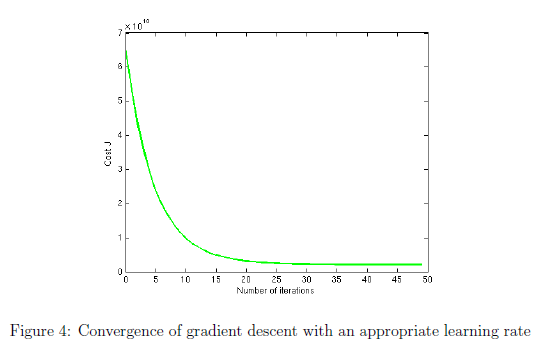

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

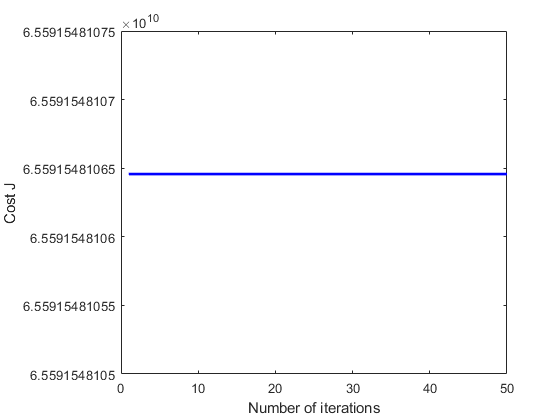

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.659574
110631.048958
-6649.472950


% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = [1, 1650, 3] * theta; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $182861695.021679

## 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

Theta computed from the normal equations:
0.000000
0.000000
0.000000

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

Predicted price of a 1650 sq-ft, 3 br house (using normal equations):
 $

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

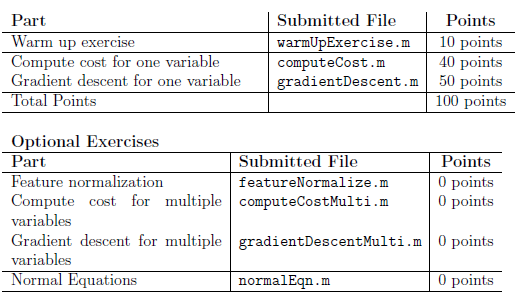

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.